load C:\nobackup\_phd_work\_battery_soh\_dataset\data.matr.io\2017-05-12_batchdata_updated_struct_errorcorrect.mat
trainData = batch;
clear batch
clear batch_date

% load C:\nobackup\_phd_work\_battery_soh\_dataset\data.matr.io\2017-05-12_batchdata_updated_struct_errorcorrect.mat
% trainData = batch;
% clear batch
% clear batch_date
% 
% load C:\nobackup\_phd_work\_battery_soh\_dataset\data.matr.io\2017-05-12_batchdata_updated_struct_errorcorrect.mat
% trainData = batch;
% clear batch
% clear batch_date

%['C:/nobackup/_phd_work/_battery_soh/_dataset/data.matr.io/2017-05-12_batchdata_updated_struct_errorcorrect.mat',
%           'C:/nobackup/_phd_work/_battery_soh/_dataset/data.matr.io/2017-06-30_batchdata_updated_struct_errorcorrect.mat',
%           'C:/nobackup/_phd_work/_battery_soh/_dataset/data.matr.io/2018-04-12_batchdata_updated_struct_errorcorrect.mat']


load ../B0005.mat
%load ../B0006.mat
%load ../B0007.mat


cap_gen_05_org = extract_discharge(B0005);
%cap_gen_06_org = extract_discharge(B0006);
%cap_gen_07_org = extract_discharge(B0007);

data_gen_05 = extract_feature_all_v3(B0005,0,cap_gen_05_org);
%data_gen_06 = extract_feature_all_v3(B0006,0,cap_gen_06_org);
%data_gen_07 = extract_feature_all_v3(B0007,0,cap_gen_07_org);

i=3 

i = 3

policy = trainData(i).policy 

policy = '3_6C-80PER_3_6C'

policy_readable = trainData(i).policy_readable 

policy_readable = '3.6C(80%)-3.6C'

channel_id = trainData(i).channel_id

channel_id = "3"

cycle_life = trainData(i).cycle_life

cycle_life = 1177

chargetime = trainData(i).summary.chargetime

chargetime =          0
   13.3414
   13.3415
   13.4258
   13.3412
   13.3413
   13.4257
   13.4256
   13.3414
   13.3413


cycle = trainData(i).summary.cycle

cycle =      1
     2
     3
     4
     5
     6
     7
     8
     9
    10


IR = trainData(i).summary.IR

IR =          0
    0.0169
    0.0168
    0.0167
    0.0167
    0.0167
    0.0167
    0.0167
    0.0167
    0.0167


QCharge = trainData(i).summary.QCharge

QCharge =          0
    1.0798
    1.0811
    1.0819
    1.0825
    1.0828
    1.0831
    1.0834
    1.0835
    1.0836


QDischarge = trainData(i).summary.QDischarge

QDischarge =          0
    1.0799
    1.0813
    1.0822
    1.0827
    1.0830
    1.0833
    1.0837
    1.0837
    1.0838


Vdlin = trainData(i).Vdlin

Vdlin =     3.5000
    3.4985
    3.4970
    3.4955
    3.4940
    3.4925
    3.4910
    3.4895
    3.4880
    3.4865


trainData(i).Vdlin

ans =     3.5000
    3.4985
    3.4970
    3.4955
    3.4940
    3.4925
    3.4910
    3.4895
    3.4880
    3.4865


cycleNum = 2

cycleNum = 2

cycleNum1 = 100

cycleNum1 = 100

size ( trainData(3).cycles(2).t )

ans =         1124           1


trainData(3).cycles(2).t 

ans =          0
    0.0025
    0.0029
    0.0032
    0.0036
    0.0040
    0.0043
    0.0045
    0.0048
    0.0051


% trainData(3).cycles(1).t(2:3,:)
 
trainData(3).cycles(cycleNum).t 

ans =          0
    0.0025
    0.0029
    0.0032
    0.0036
    0.0040
    0.0043
    0.0045
    0.0048
    0.0051


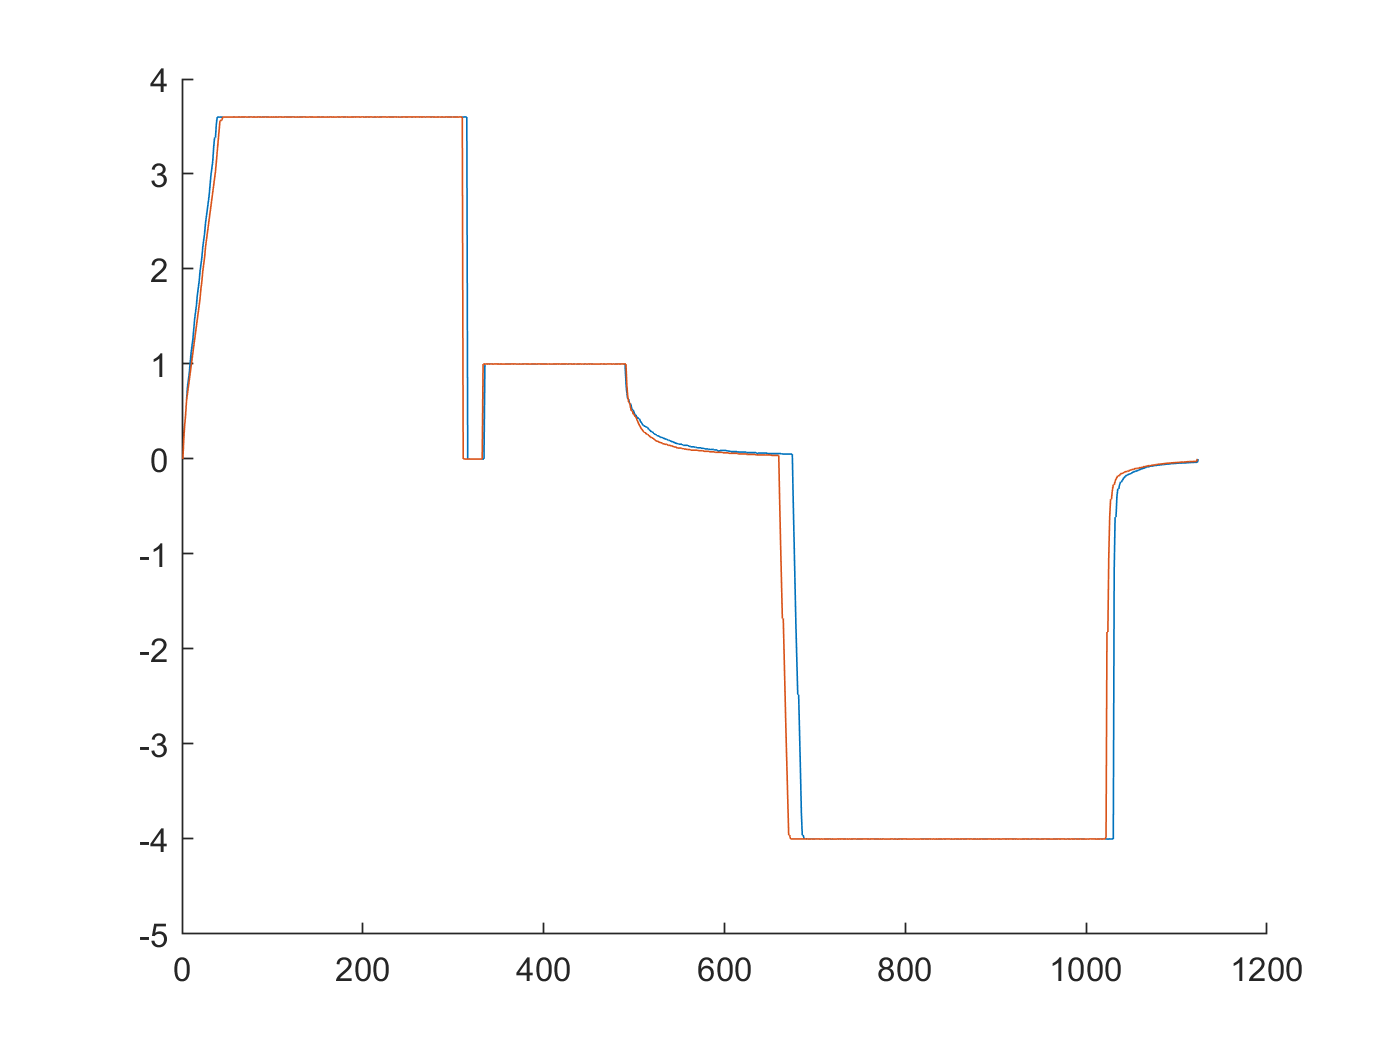

figure
hold on
plot(trainData(3).cycles(cycleNum).I)
plot(trainData(3).cycles(cycleNum1).I)
hold off

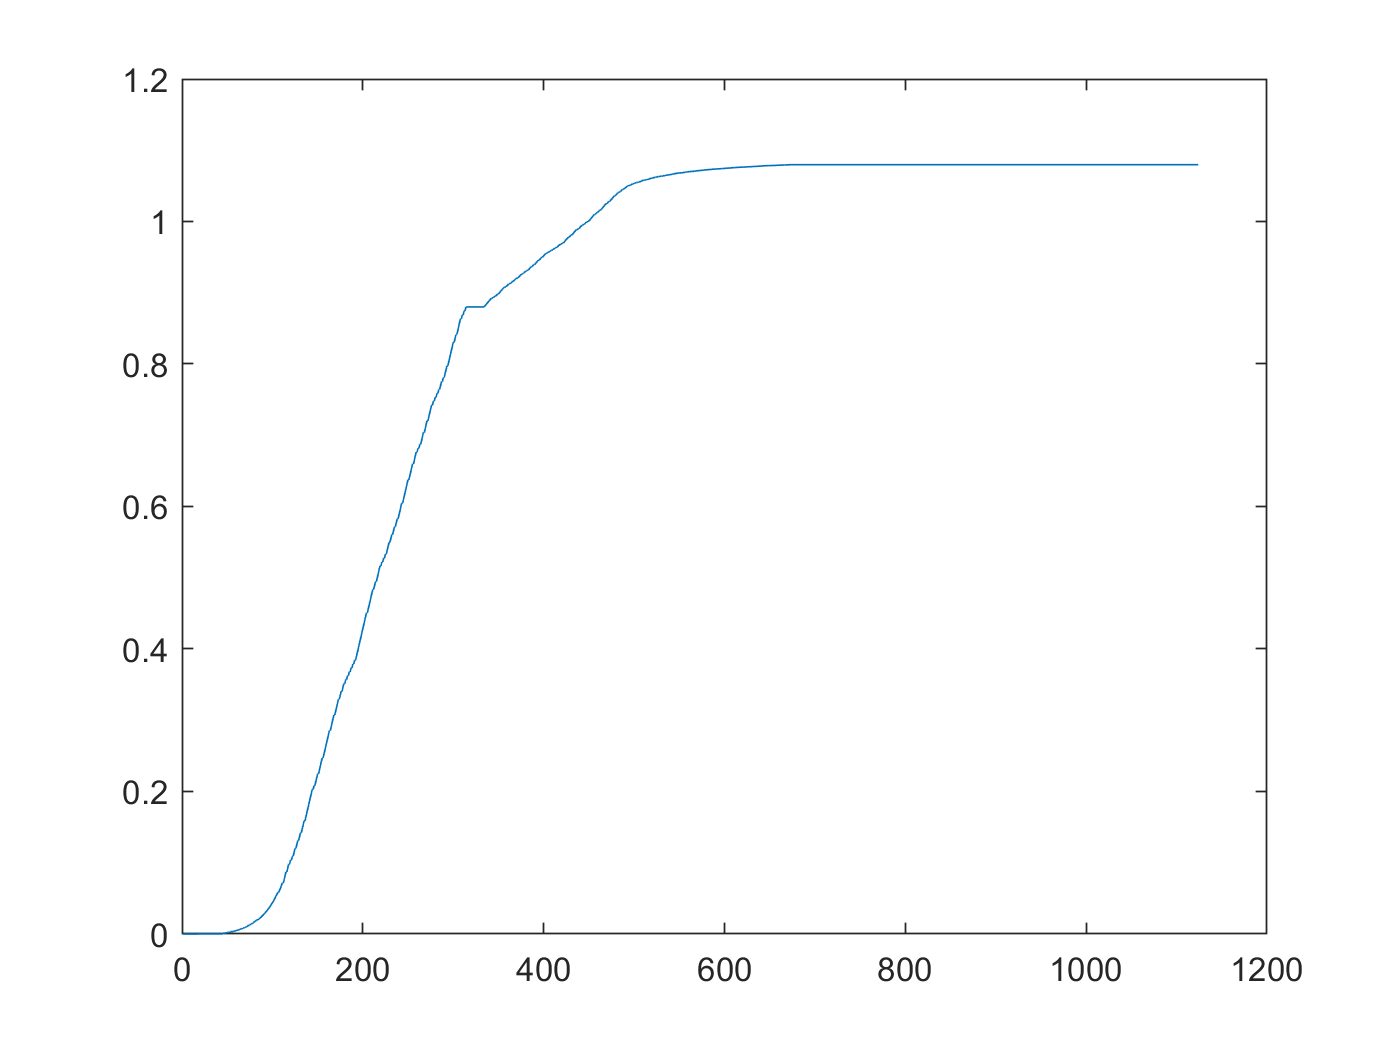



plot(trainData(3).cycles(cycleNum).Qc)

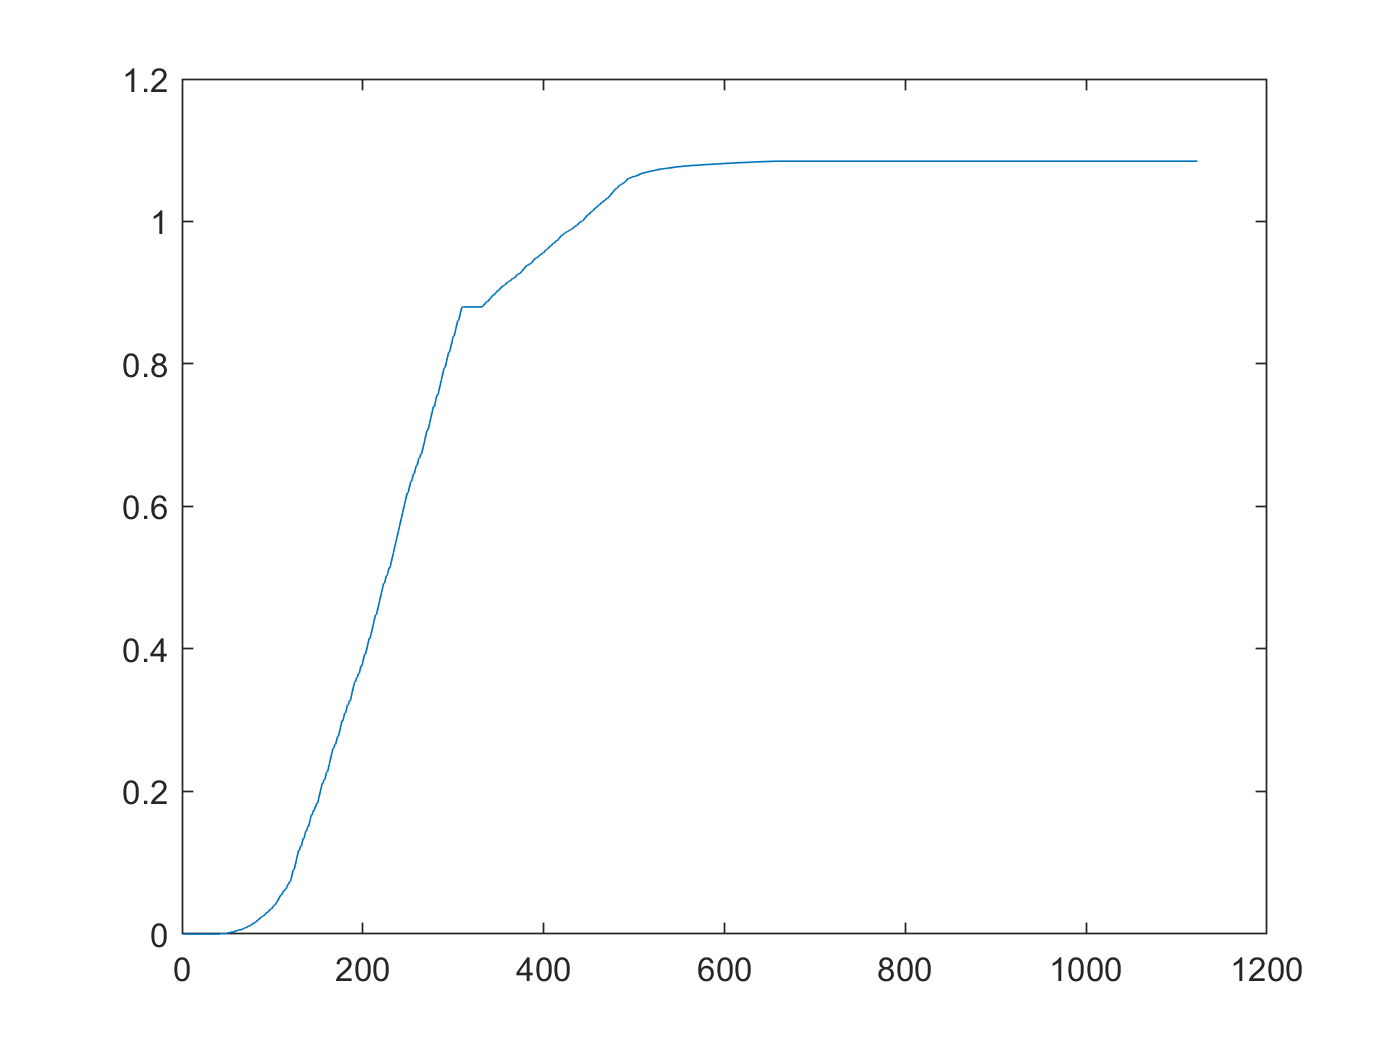

plot(trainData(3).cycles(cycleNum1).Qc)

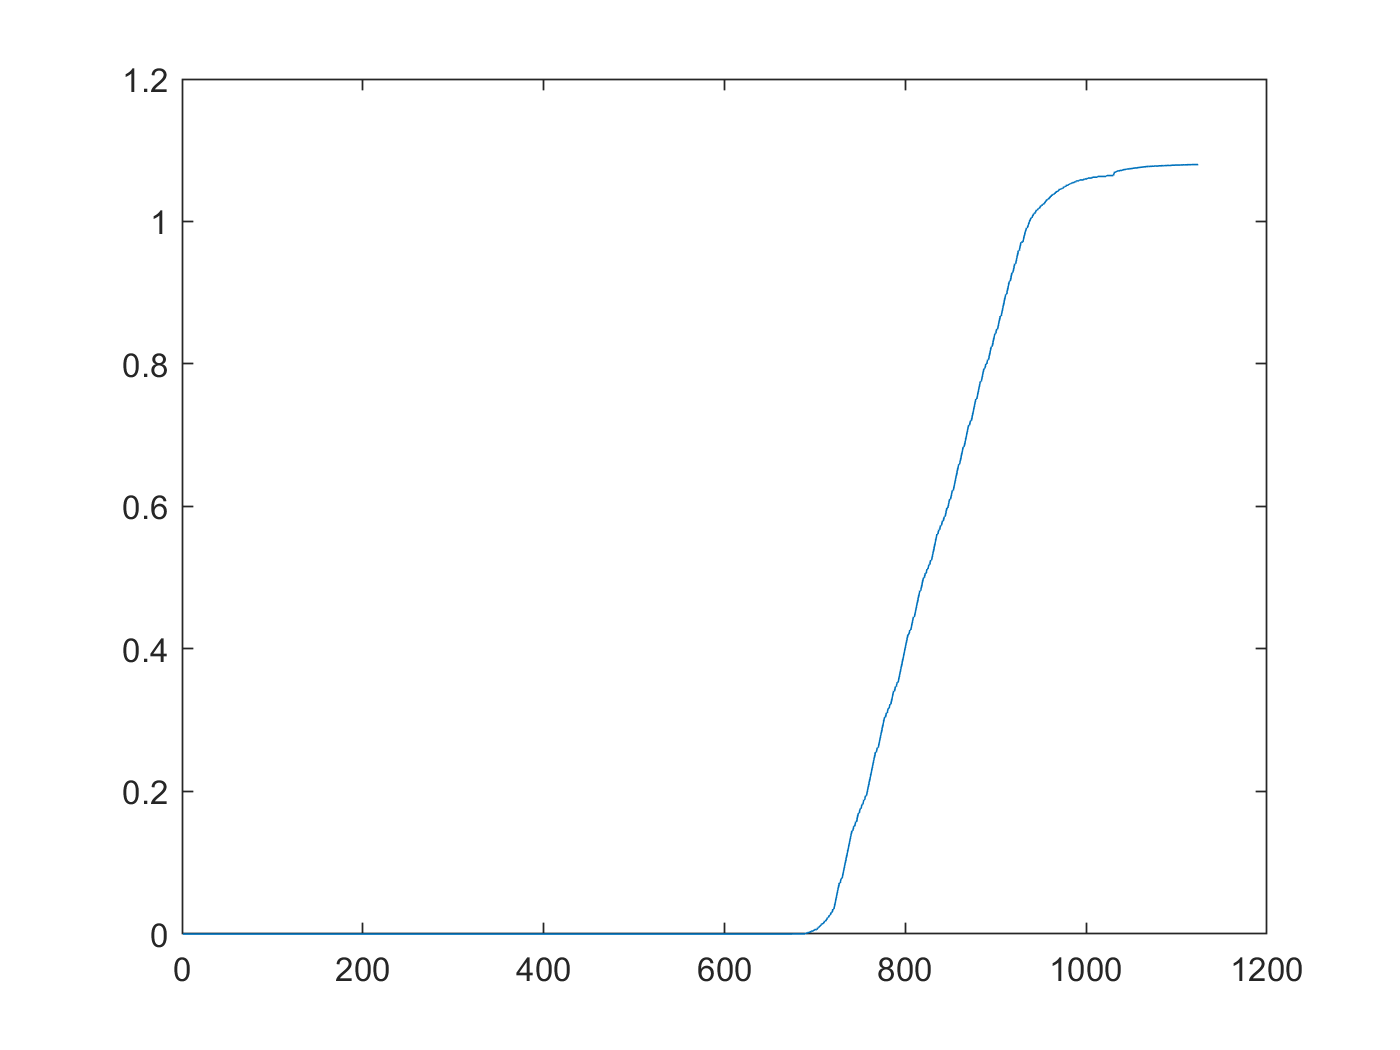

plot(trainData(3).cycles(cycleNum).Qd)

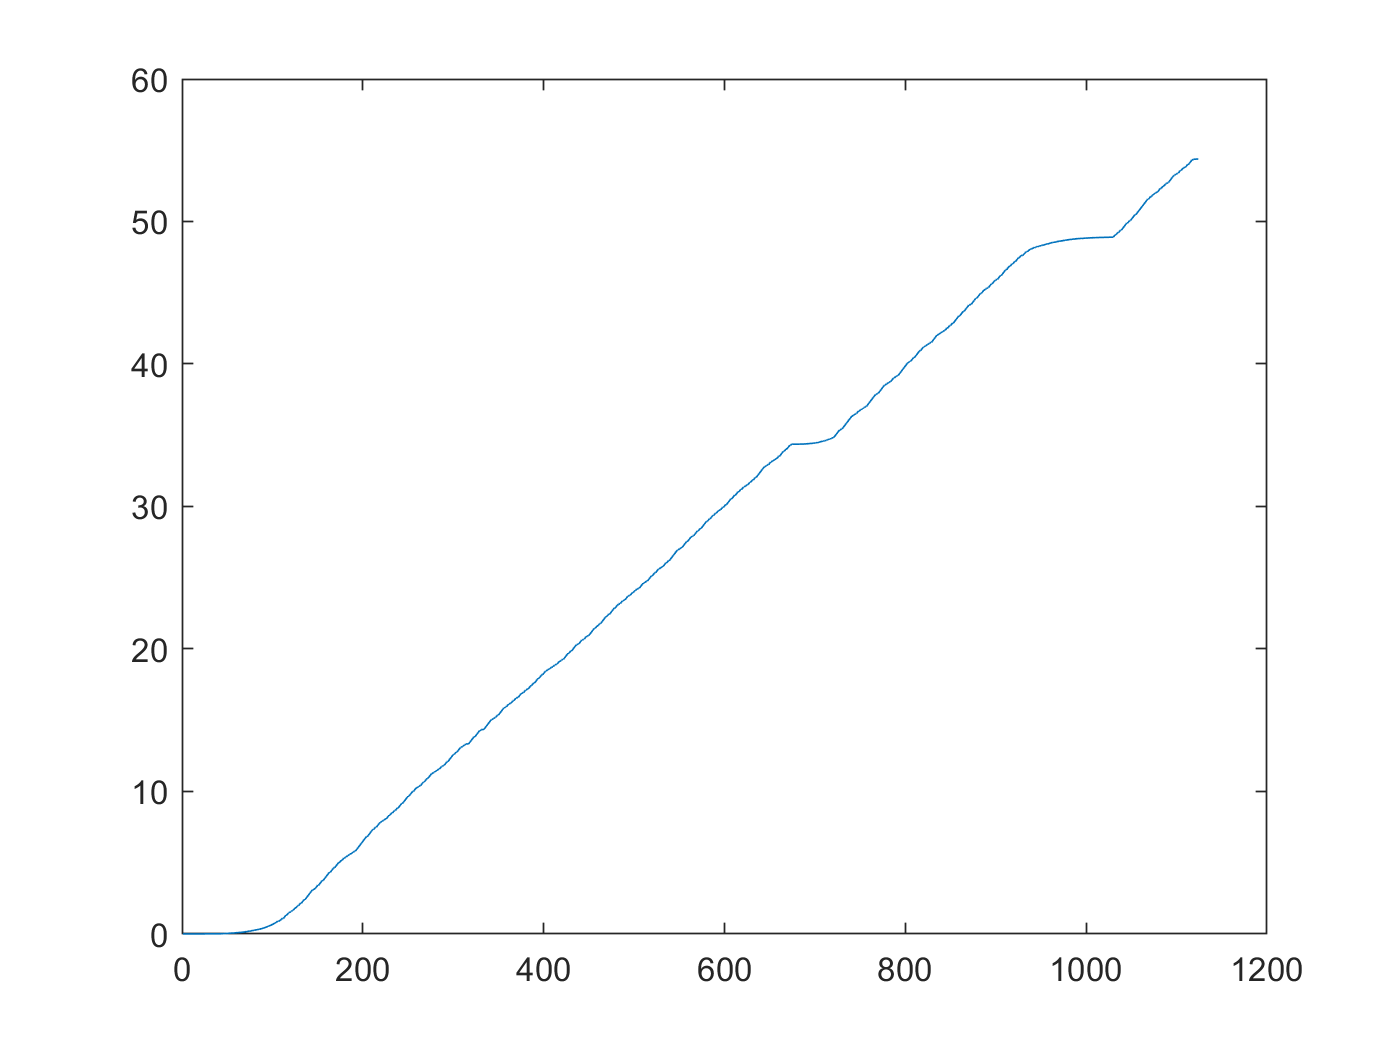

plot(trainData(3).cycles(cycleNum).t)

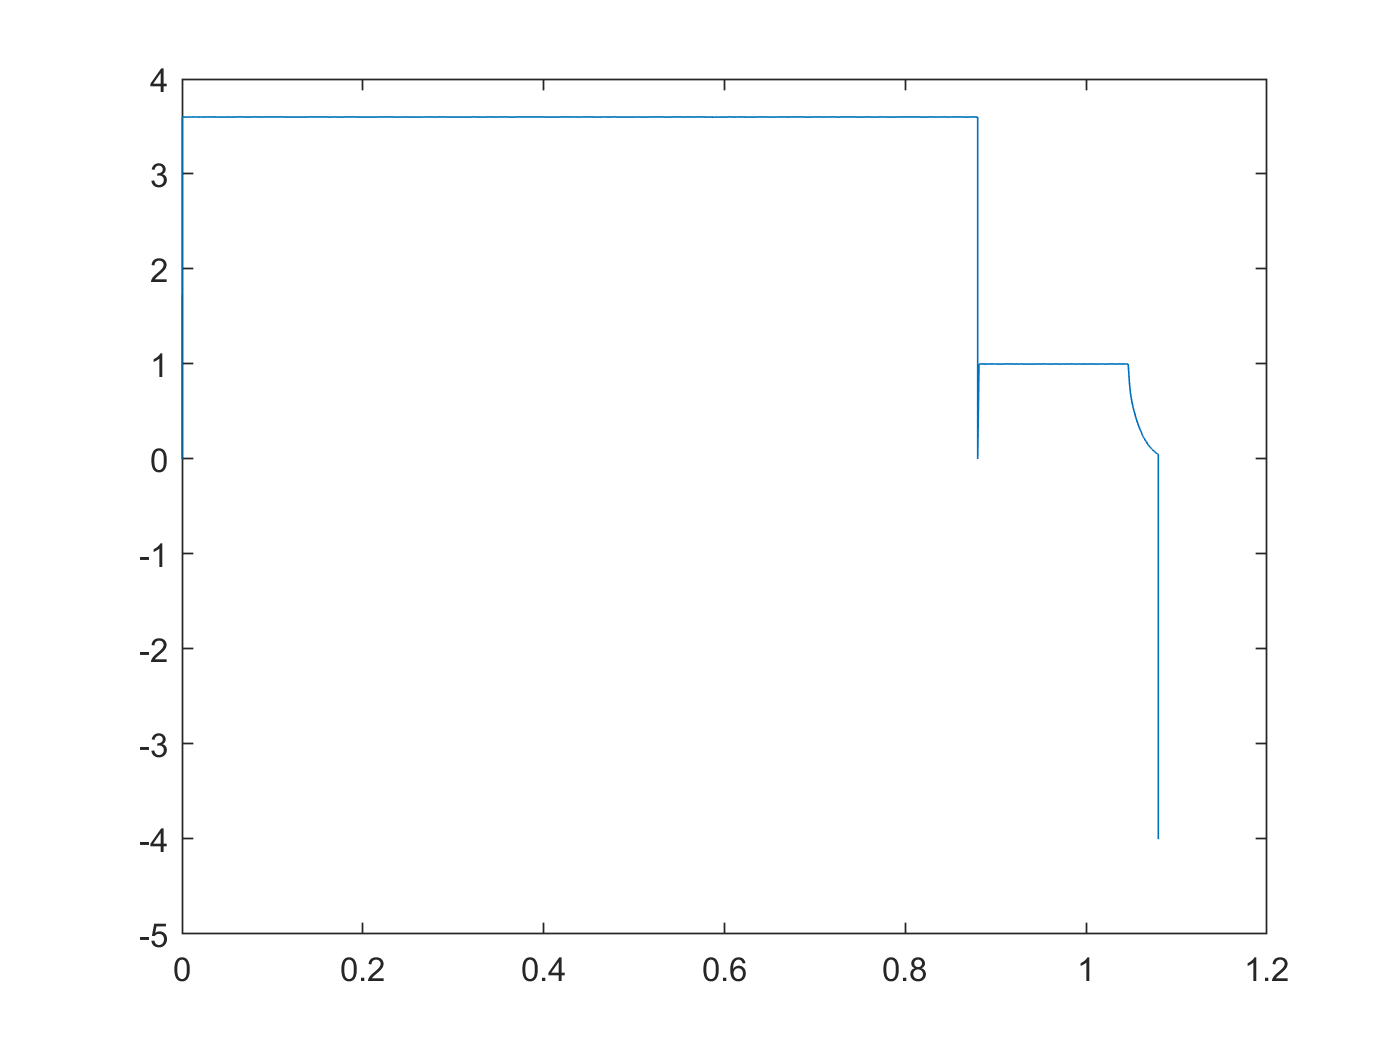

plot(trainData(3).cycles(cycleNum).Qc, trainData(3).cycles(cycleNum).I)

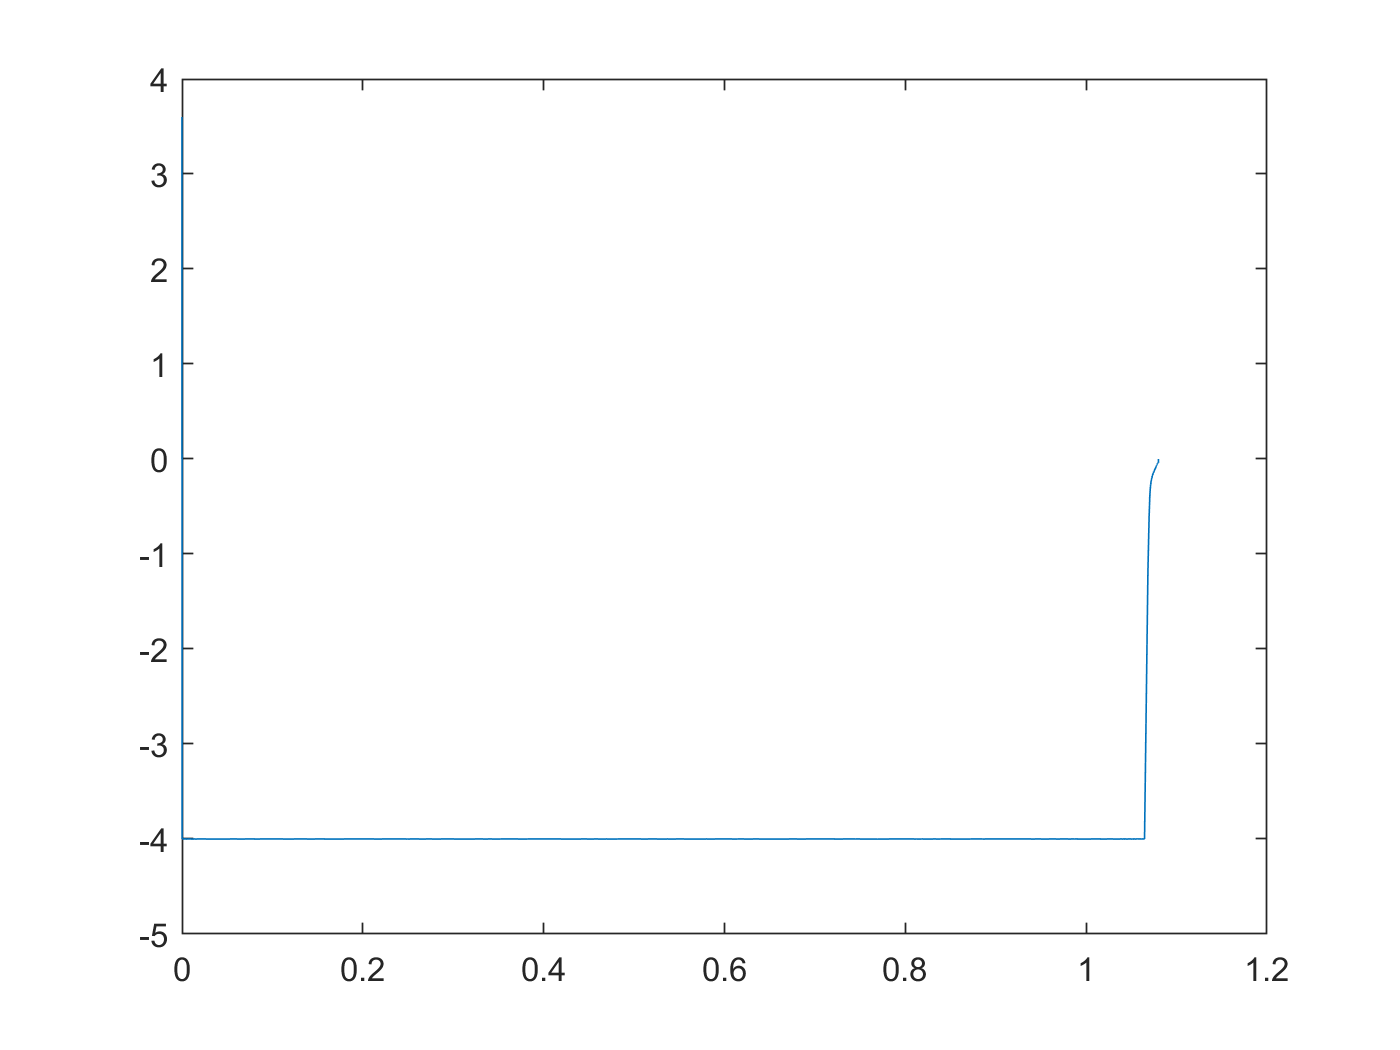

plot(trainData(3).cycles(cycleNum).Qd, trainData(3).cycles(cycleNum).I)

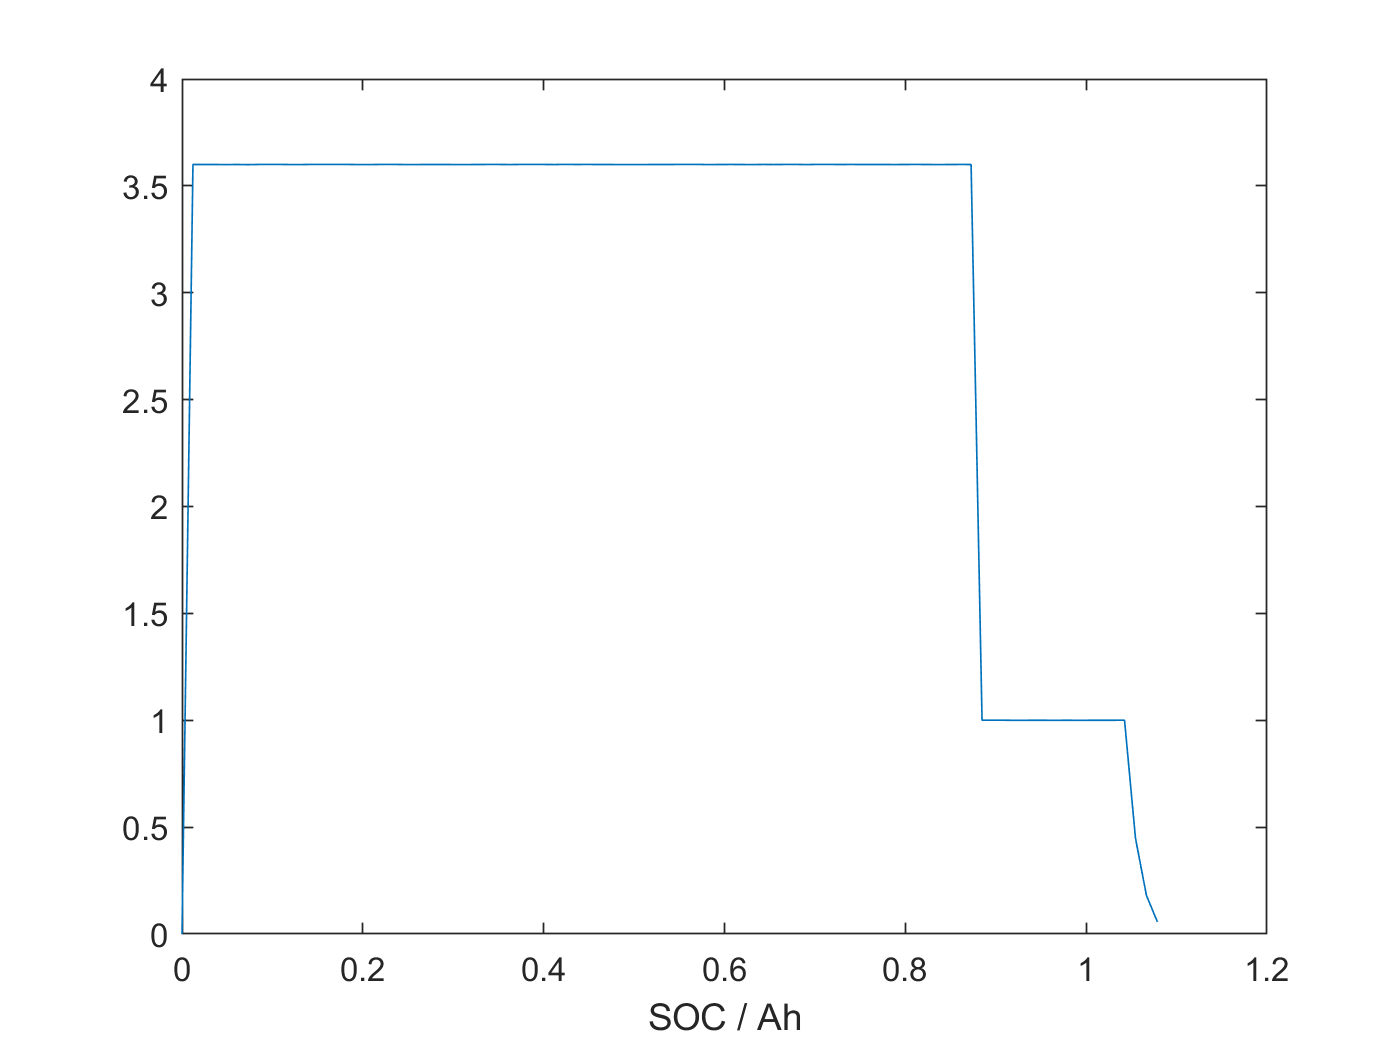

[x_c, index] = unique(trainData(3).cycles(cycleNum).Qc,"first");
%[x_c, index] = unique(trainData(3).cycles(cycleNum).Qc)
y_c = trainData(3).cycles(cycleNum).I(index);
new_x_c = linspace(0,1.2,100);
new_y_c = interp1(x_c,y_c,new_x_c,'linear');
plot(new_x_c,new_y_c);
xlabel("SOC / Ah")

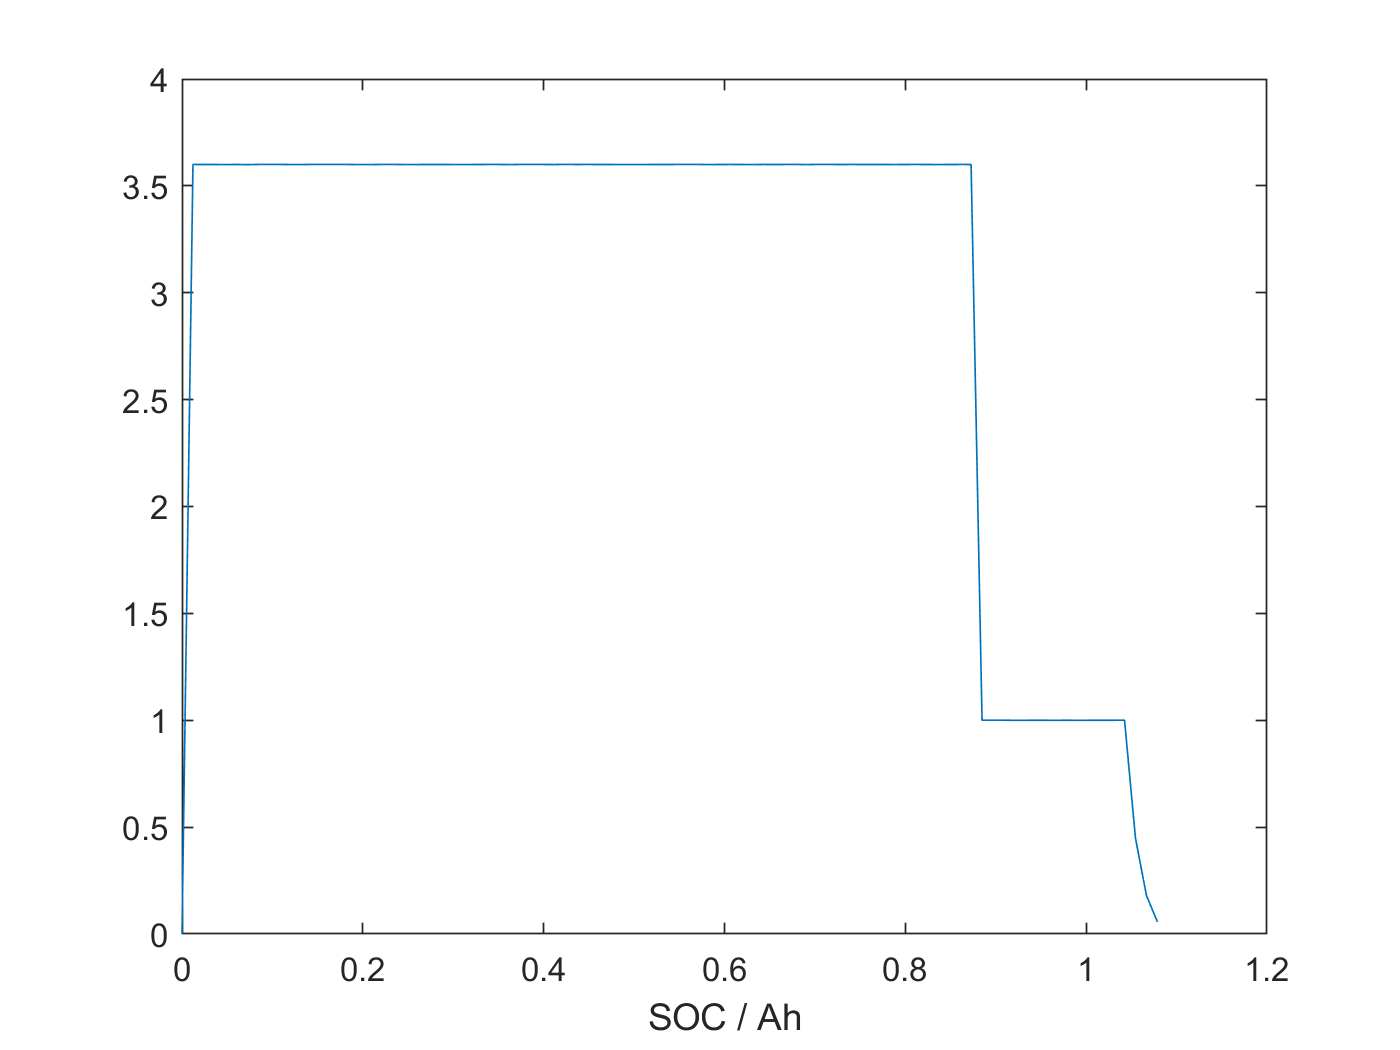


[x_c, index] = unique(trainData(3).cycles(cycleNum).Qc,"last");
%[x_c, index] = unique(trainData(3).cycles(cycleNum).Qc)
y_c = trainData(3).cycles(cycleNum).I(index);
new_x_c = linspace(0,1.2,100);
new_y_c = interp1(x_c,y_c,new_x_c,'linear');
plot(new_x_c,new_y_c);
xlabel("SOC / Ah")

% https://kr.mathworks.com/matlabcentral/answers/88808-fill-nans-in-array-with-last-value?s_tid=ta_ans_results
idx = (~isnan(new_y_c ))

idx = 1×100 logical array
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1


vr = new_y_c(idx); %v non nan
new_y_c_fix = vr(cumsum(idx)) %use cumsum to build index into vr

new_y_c_fix =          0    3.6001    3.5999    3.6001    3.5995    3.6001    3.5994    3.6001    3.6001    3.6002    3.5998    3.5999    3.6004    3.6003    3.6002    3.6002    3.5998    3.5996    3.6001    3.6004    3.5999    3.5997    3.6000    3.6000    3.6000    3.5998    3.5999    3.5999    3.6002    3.6001    3.5998    3.6003    3.6001    3.6001    3.5998    3.6005    3.6000    3.6002    3.5999    3.6000    3.5998    3.5999    3.5997    3.6001    3.5999    3.6001    3.6001    3.6004    3.5996    3.6000


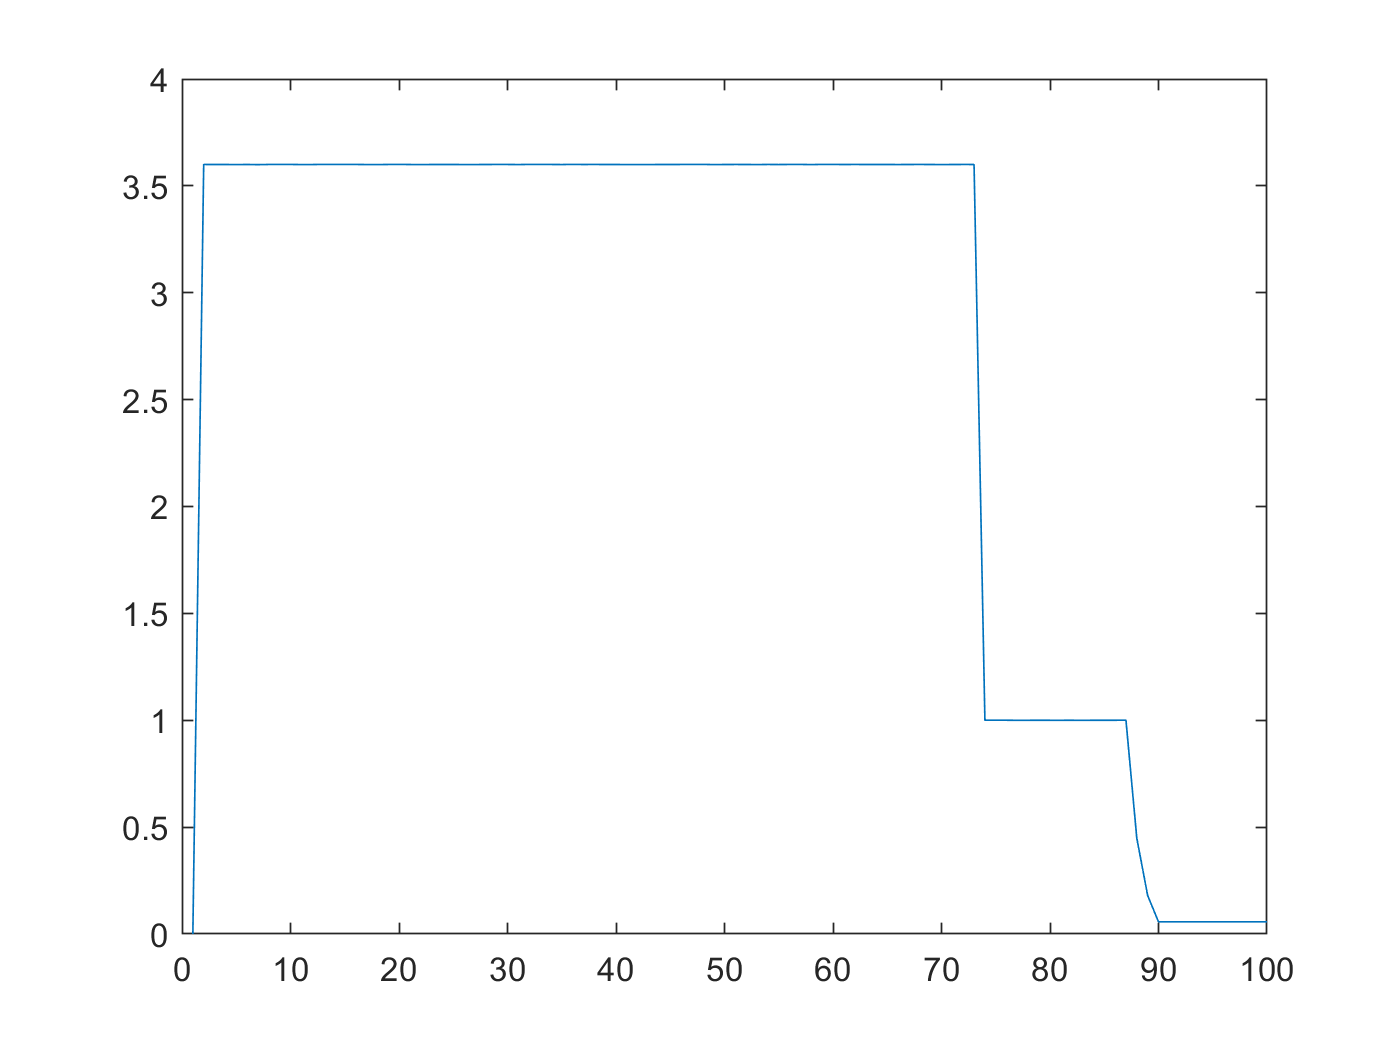

plot(new_y_c_fix)

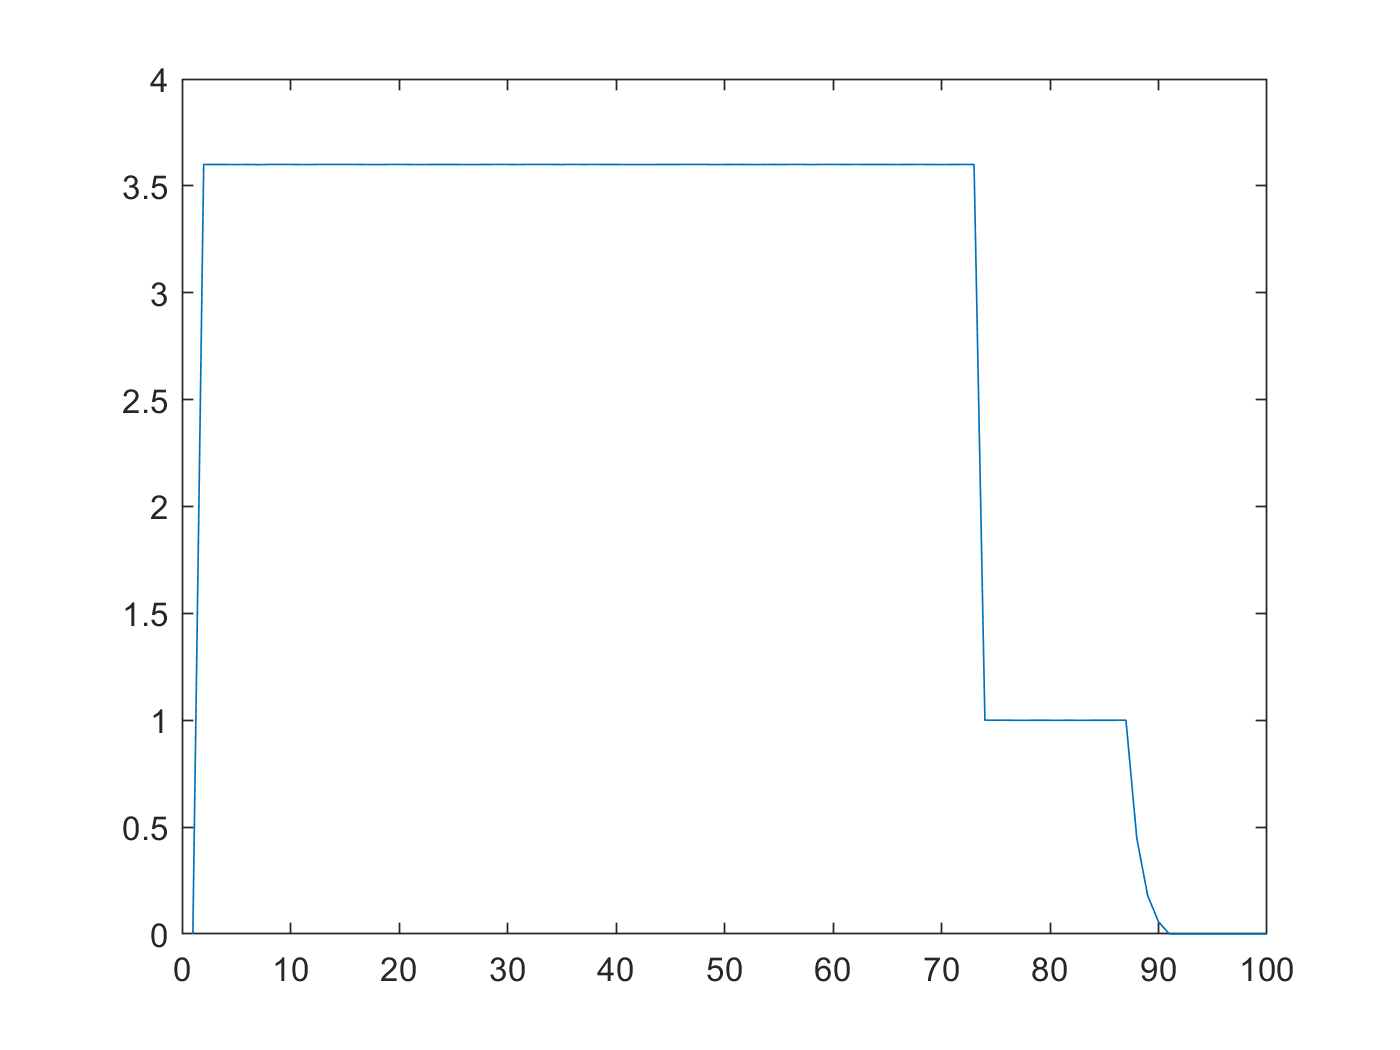

% https://kr.mathworks.com/matlabcentral/answers/6038-convert-zeros-to-nan
% https://kr.mathworks.com/matlabcentral/answers/85568-how-to-convert-nan-to-zero?s_tid=ta_ans_results

new_y_c_fix_fill_zero = new_y_c;
%% not work
%new_y_c_fix_fill_zero(new_y_c_fix_fill_zero==NaN)=0;
%new_y_c_fix_fill_zeroA(find(new_y_c_fix_fill_zero==NaN)) = 0;

%% work
new_y_c_fix_fill_zero(isnan(new_y_c_fix_fill_zero)) = 0;
plot(new_y_c_fix_fill_zero)

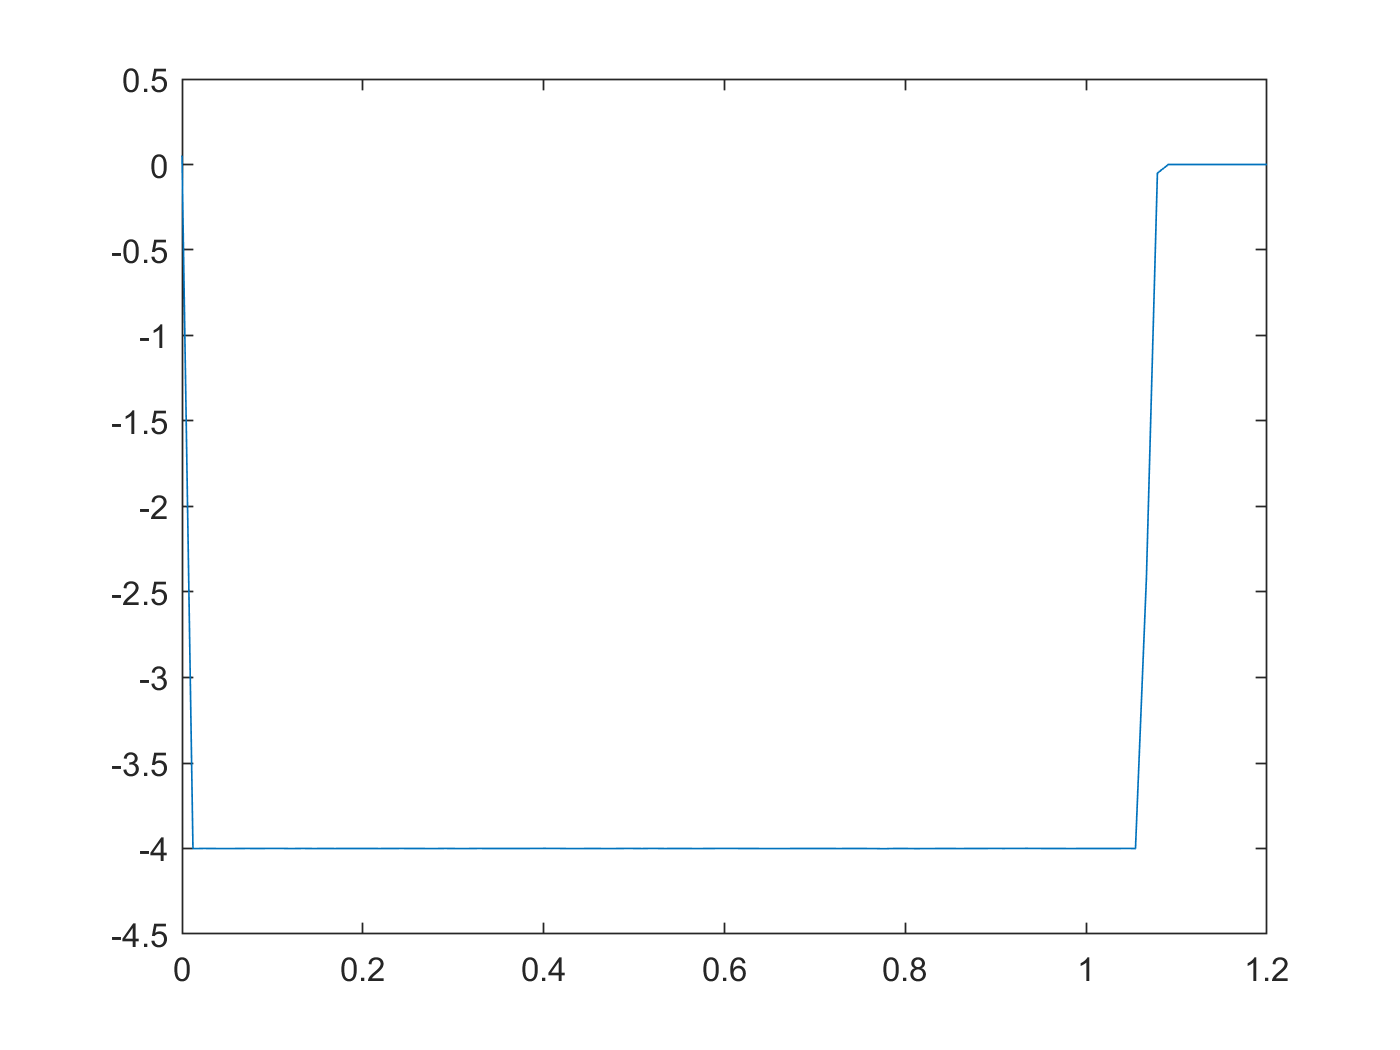

%[x_d, index] = unique(trainData(3).cycles(cycleNum).Qd);
[x_d, index] = unique(trainData(3).cycles(cycleNum).Qd,"last");

y_d = trainData(3).cycles(cycleNum).I(index);
new_x_d = linspace(0,1.2,100);
new_y_d = interp1(x_d,y_d,new_x_d,'linear'); 
new_y_d(isnan(new_y_d)) = 0;
plot(new_x_d,new_y_d);

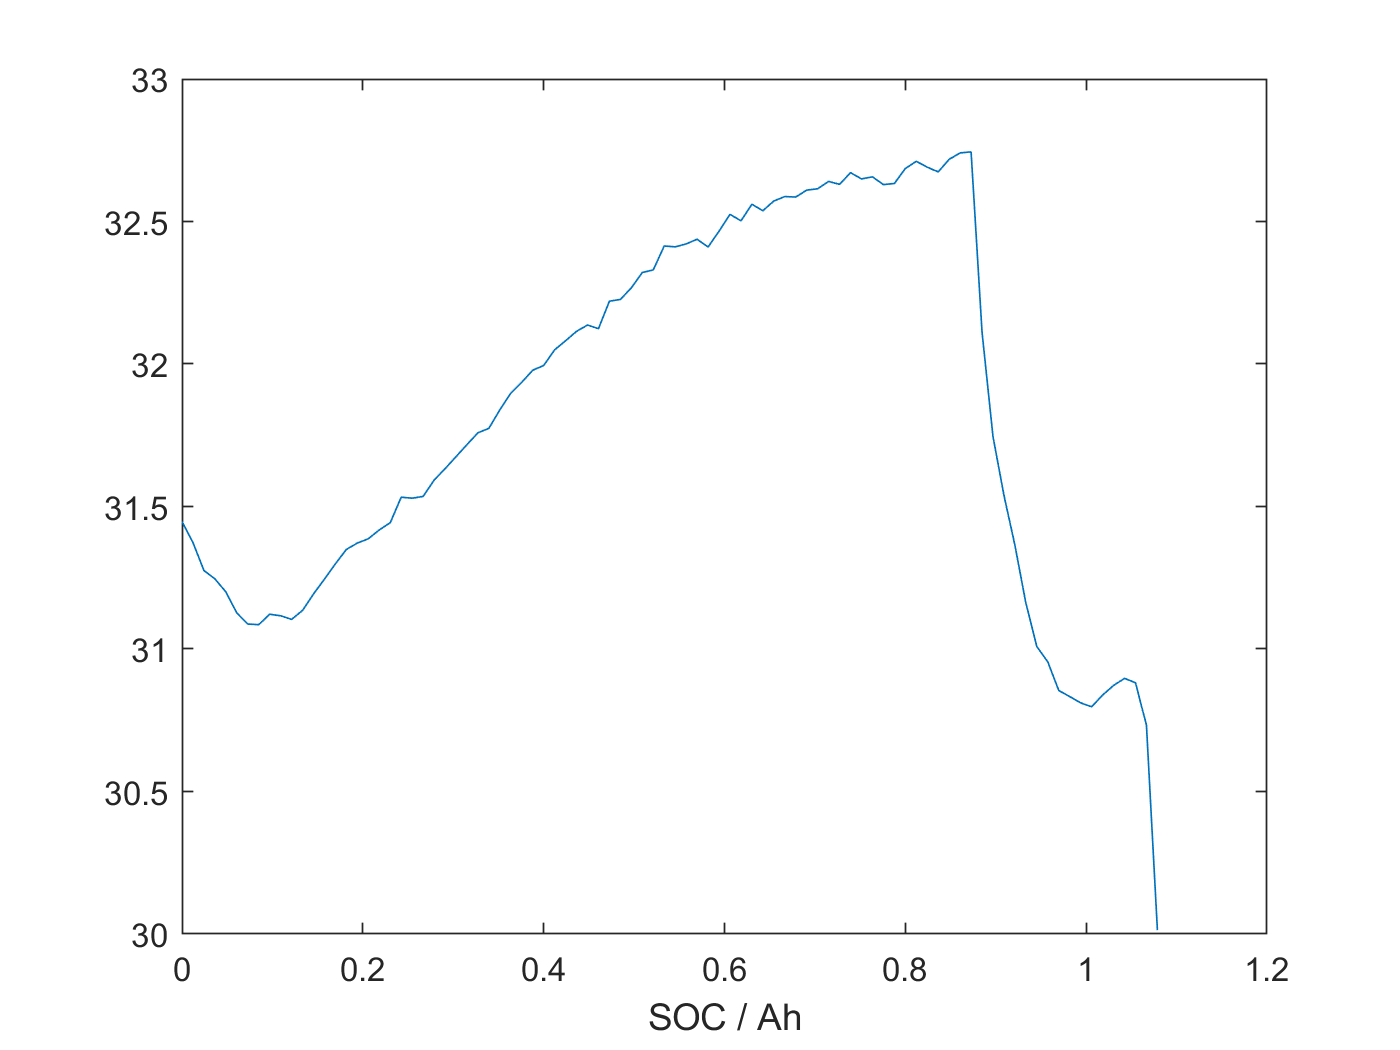

[x_c, index] = unique(trainData(3).cycles(cycleNum).Qc,"last");
%[x_c, index] = unique(trainData(3).cycles(cycleNum).Qc)
y_c = trainData(3).cycles(cycleNum).T(index);
new_x_c = linspace(0,1.2,100);
new_y_c = interp1(x_c,y_c,new_x_c,'linear');
plot(new_x_c,new_y_c);
xlabel("SOC / Ah")

% https://kr.mathworks.com/matlabcentral/answers/88808-fill-nans-in-array-with-last-value?s_tid=ta_ans_results
idx = (~isnan(new_y_c ))

idx = 1×100 logical array
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1


vr = new_y_c(idx); %v non nan
new_y_c_fix = vr(cumsum(idx)) %use cumsum to build index into vr

new_y_c_fix =    31.4471   31.3735   31.2755   31.2462   31.2004   31.1265   31.0876   31.0854   31.1219   31.1165   31.1039   31.1356   31.1932   31.2452   31.2990   31.3494   31.3717   31.3868   31.4179   31.4430   31.5327   31.5291   31.5354   31.5926   31.6325   31.6747   31.7171   31.7584   31.7744   31.8391   31.8977   31.9359   31.9781   31.9948   32.0497   32.0816   32.1146   32.1367   32.1238   32.2204   32.2265   32.2673   32.3211   32.3301   32.4141   32.4110   32.4214   32.4377   32.4105   32.4660


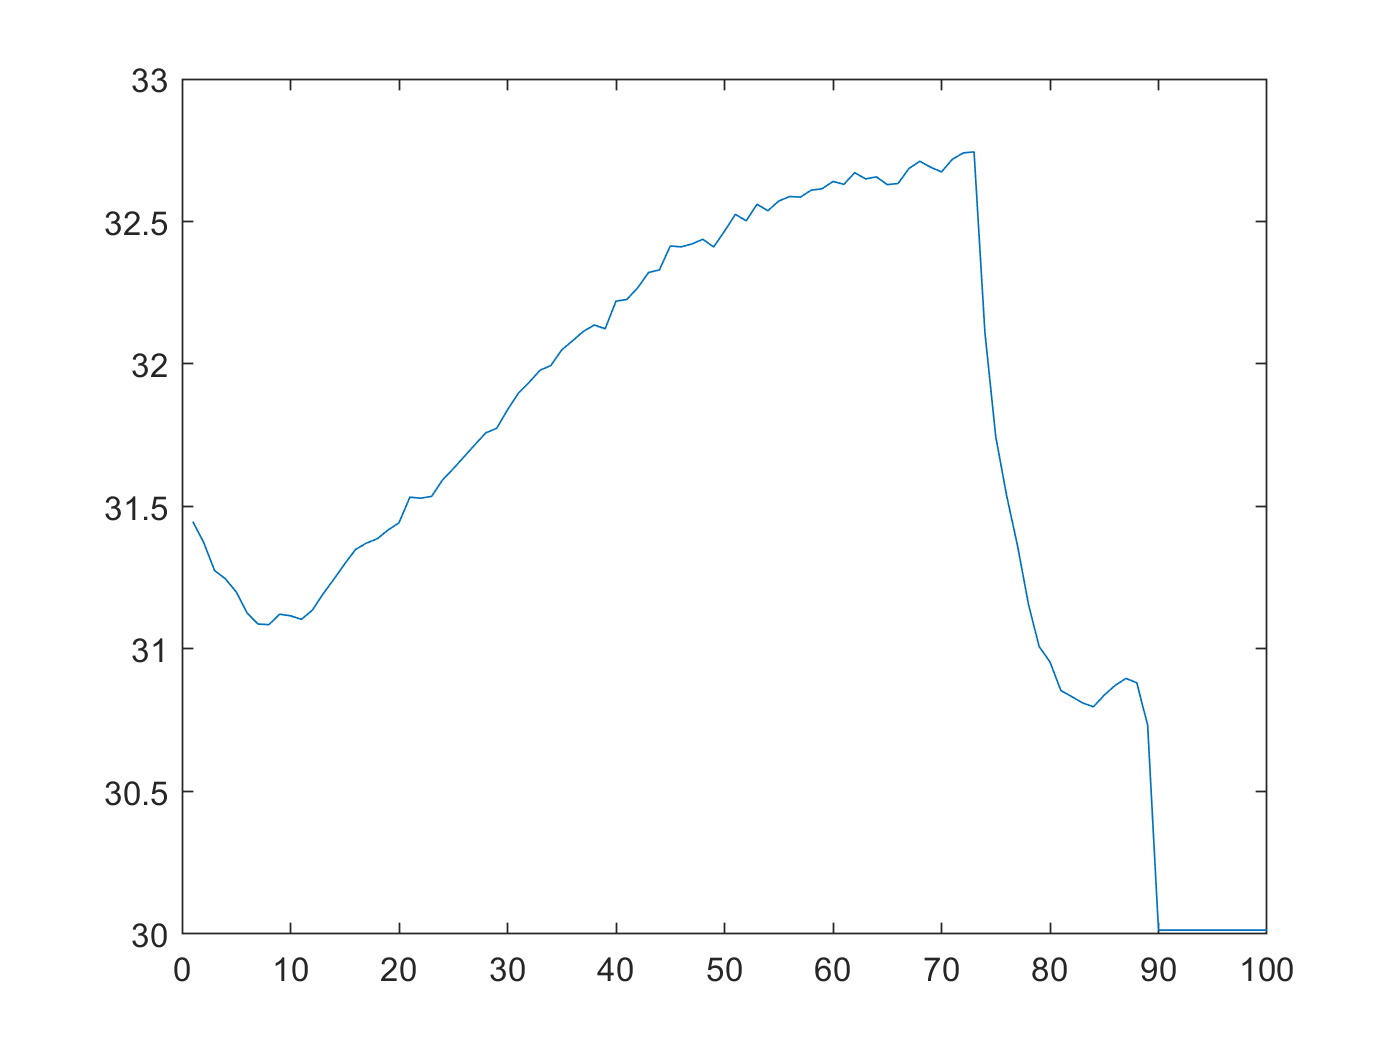

plot(new_y_c_fix)

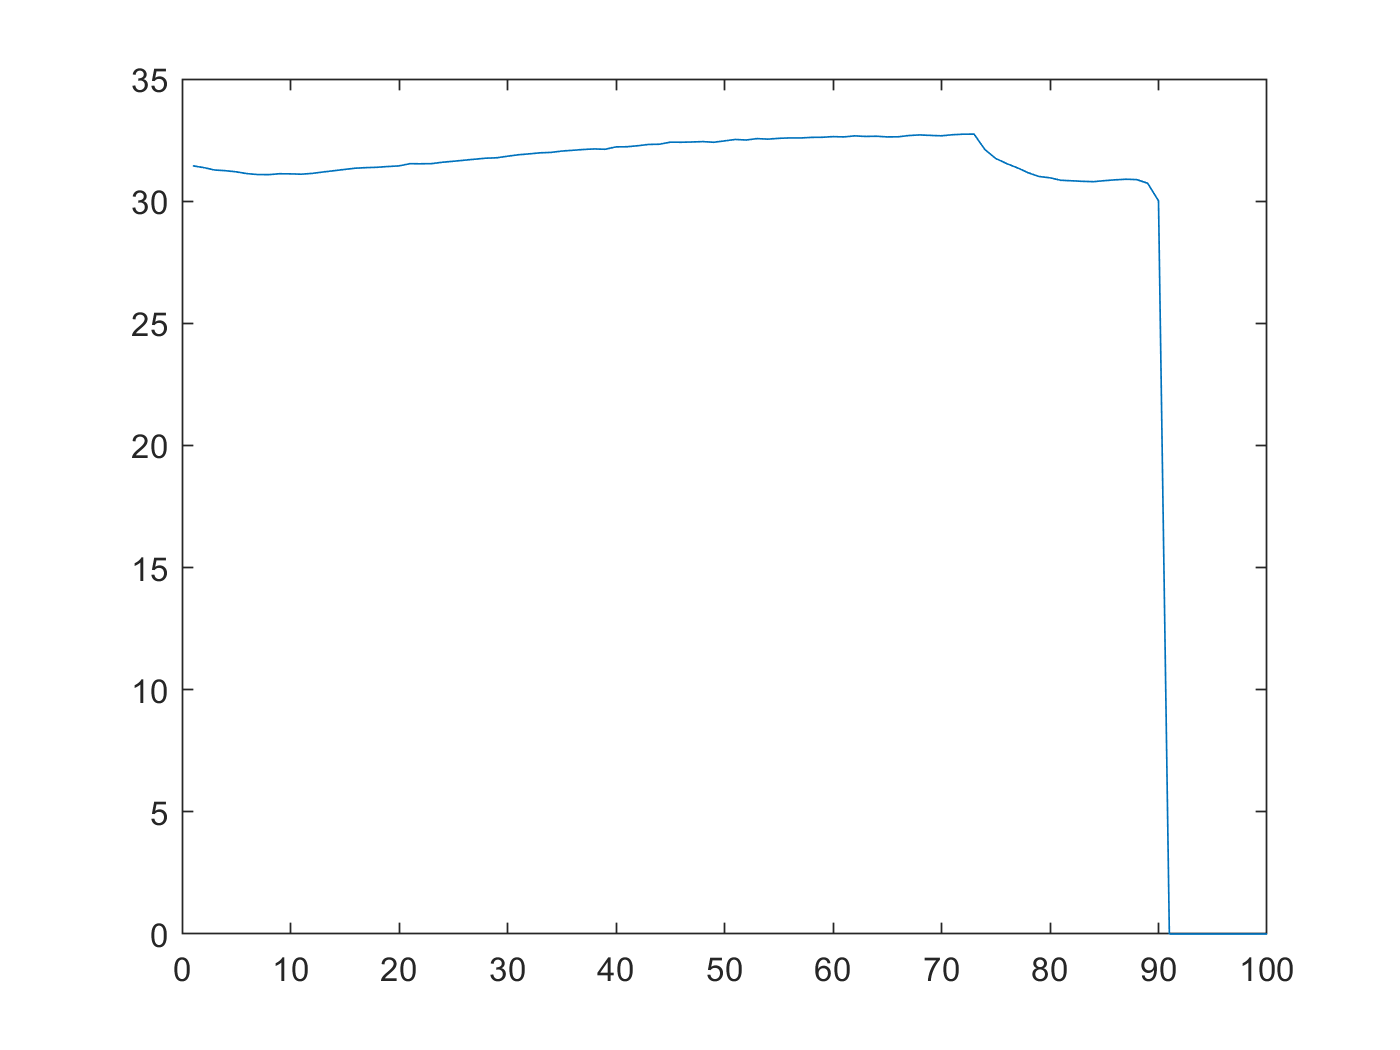

% https://kr.mathworks.com/matlabcentral/answers/6038-convert-zeros-to-nan
% https://kr.mathworks.com/matlabcentral/answers/85568-how-to-convert-nan-to-zero?s_tid=ta_ans_results

new_y_c_fix_fill_zero = new_y_c;
%% not work
%new_y_c_fix_fill_zero(new_y_c_fix_fill_zero==NaN)=0;
%new_y_c_fix_fill_zeroA(find(new_y_c_fix_fill_zero==NaN)) = 0;

%% work
new_y_c_fix_fill_zero(isnan(new_y_c_fix_fill_zero)) = 0;
plot(new_y_c_fix_fill_zero)

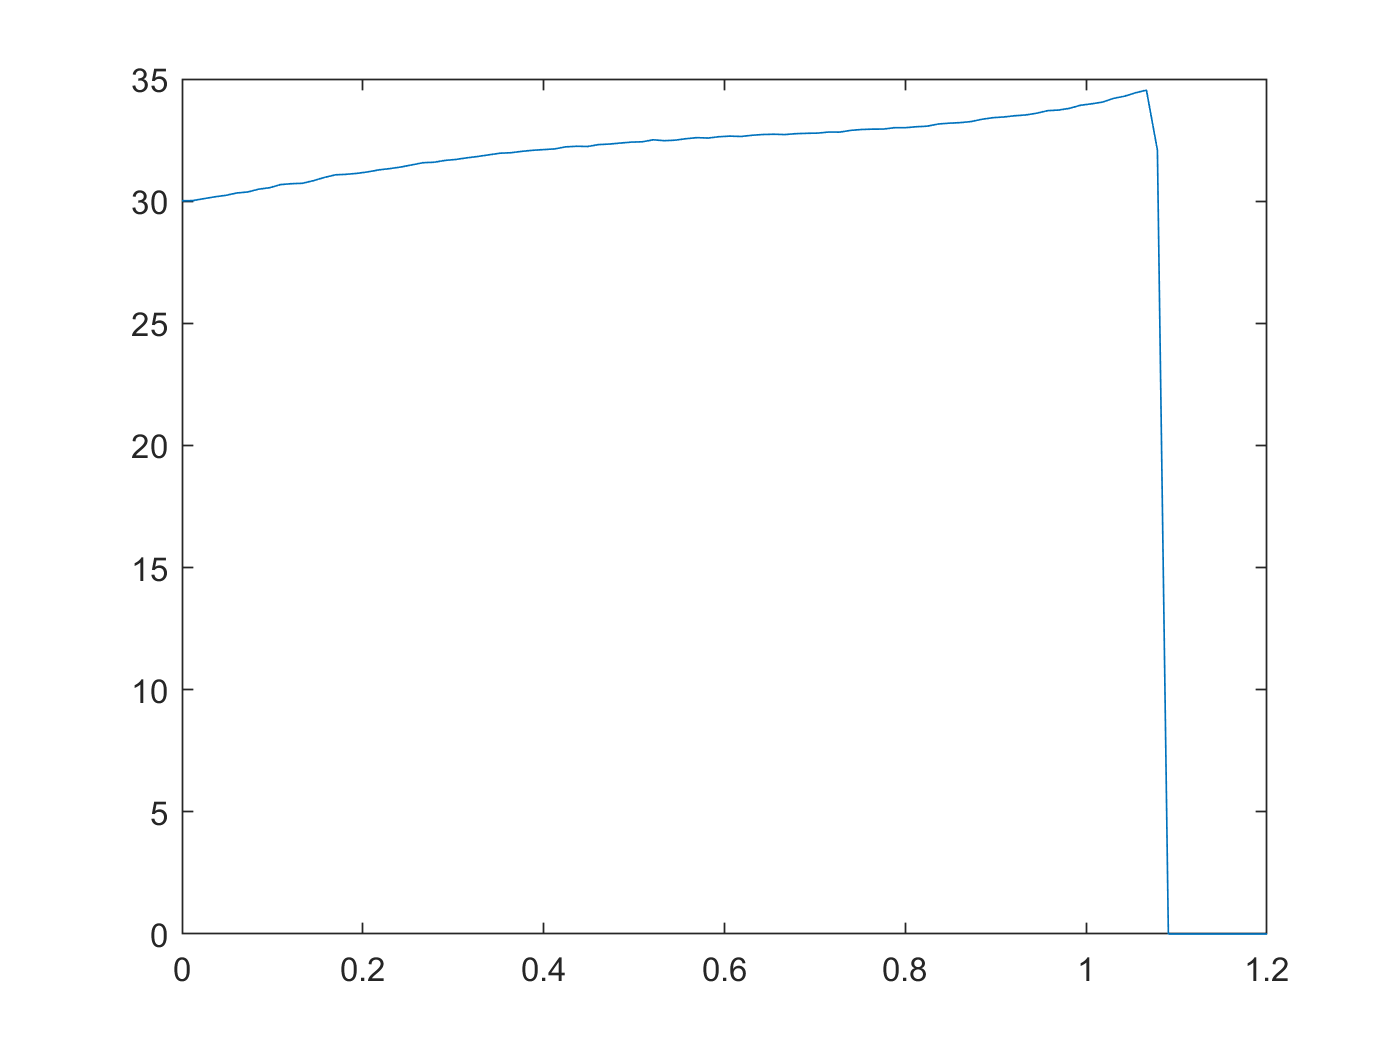

%[x_d, index] = unique(trainData(3).cycles(cycleNum).Qd);
[x_d, index] = unique(trainData(3).cycles(cycleNum).Qd,"last");

y_d = trainData(3).cycles(cycleNum).T(index);
new_x_d = linspace(0,1.2,100);
new_y_d = interp1(x_d,y_d,new_x_d,'linear'); 
new_y_d(isnan(new_y_d)) = 0;
plot(new_x_d,new_y_d);

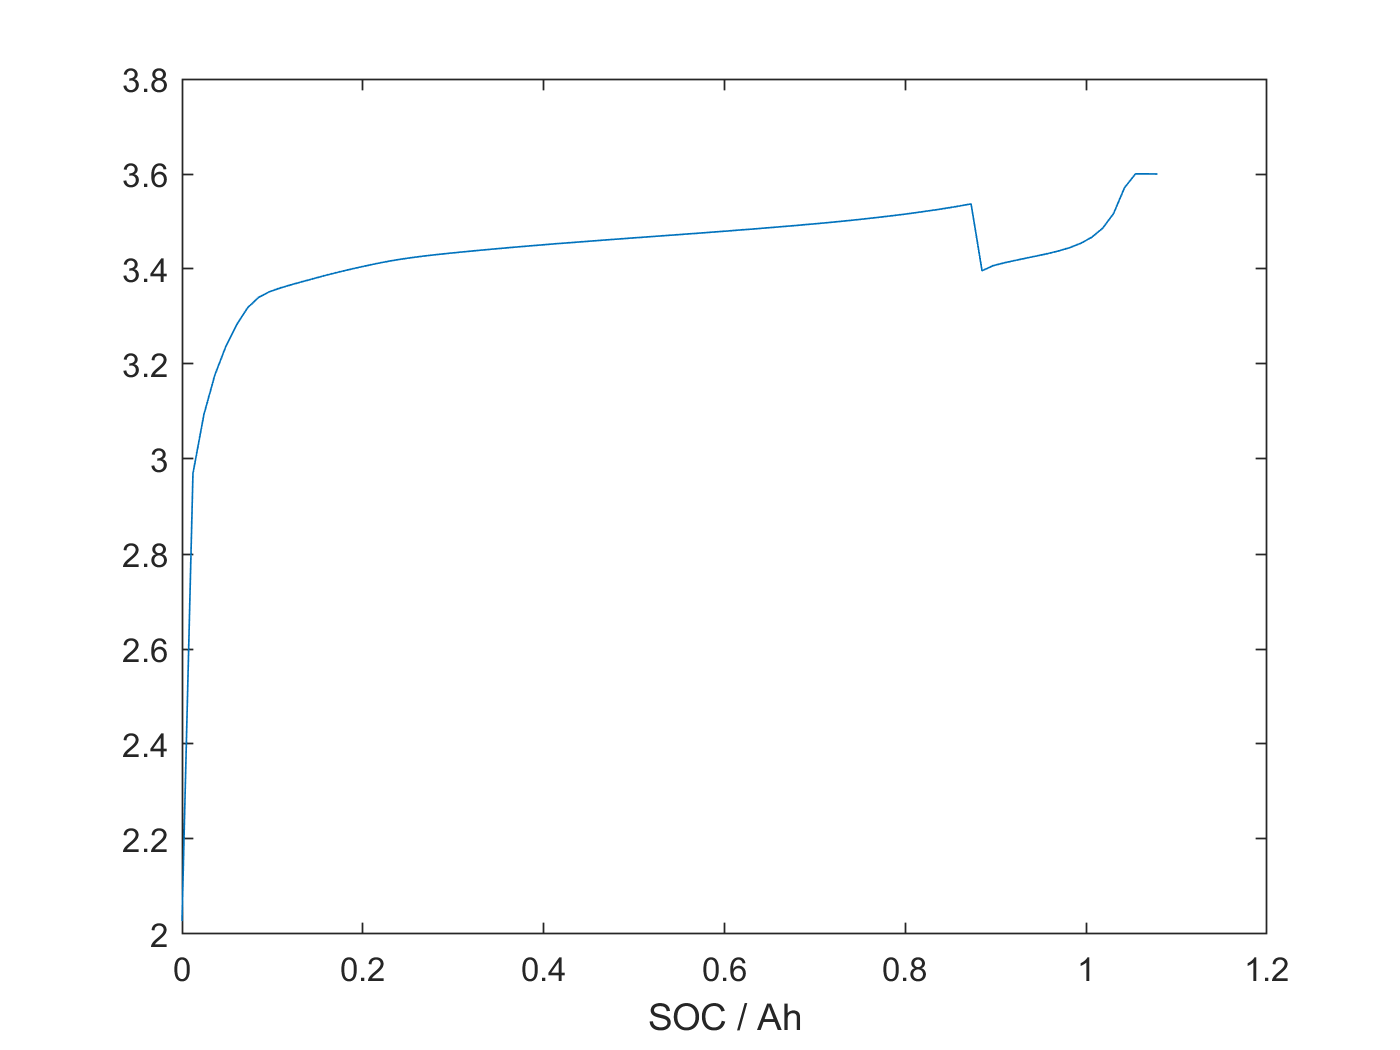

[x_c, index] = unique(trainData(3).cycles(cycleNum).Qc,"last");
%[x_c, index] = unique(trainData(3).cycles(cycleNum).Qc)
y_c = trainData(3).cycles(cycleNum).V(index);
new_x_c = linspace(0,1.2,100);
new_y_c = interp1(x_c,y_c,new_x_c,'linear');
plot(new_x_c,new_y_c);
xlabel("SOC / Ah")

% https://kr.mathworks.com/matlabcentral/answers/88808-fill-nans-in-array-with-last-value?s_tid=ta_ans_results
% https://kr.mathworks.com/matlabcentral/answers/29481-last-non-nan-observation
idx = (~isnan(new_y_c ))

idx = 1×100 logical array
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1


vr = new_y_c(idx); %v non nan
new_y_c_fix = vr(cumsum(idx)) %use cumsum to build index into vr

new_y_c_fix =     2.0272    2.9696    3.0937    3.1770    3.2370    3.2832    3.3188    3.3404    3.3524    3.3603    3.3671    3.3735    3.3797    3.3860    3.3918    3.3975    3.4027    3.4078    3.4126    3.4170    3.4207    3.4241    3.4271    3.4297    3.4322    3.4346    3.4369    3.4390    3.4411    3.4432    3.4453    3.4472    3.4492    3.4510    3.4530    3.4547    3.4565    3.4582    3.4600    3.4618    3.4634    3.4652    3.4668    3.4685    3.4702    3.4718    3.4735    3.4752    3.4769    3.4787


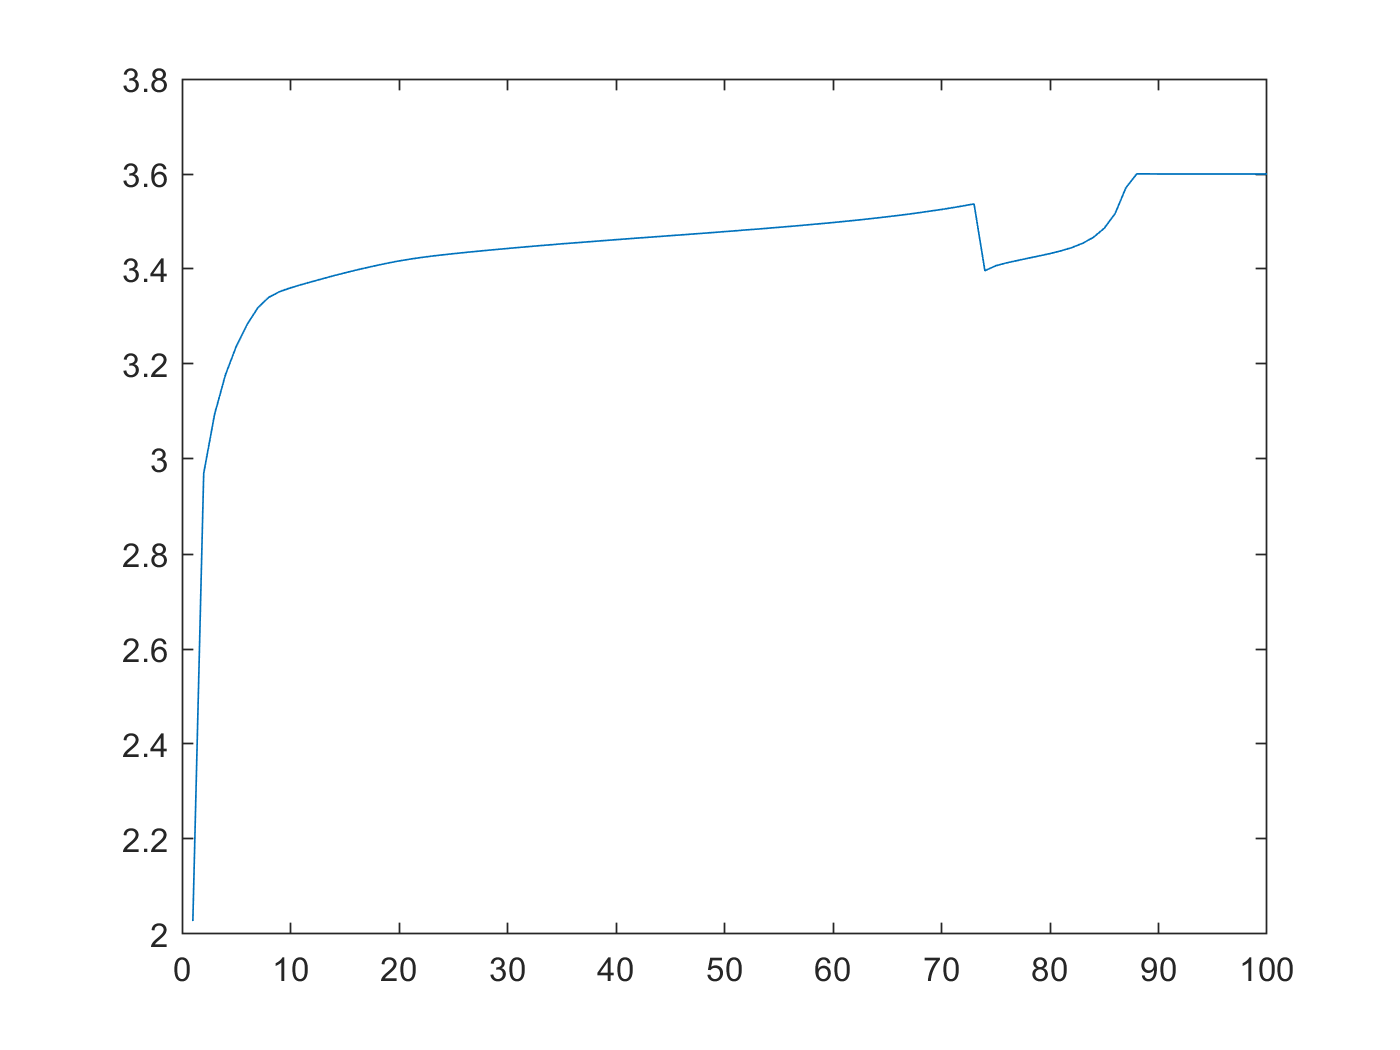

plot(new_y_c_fix)

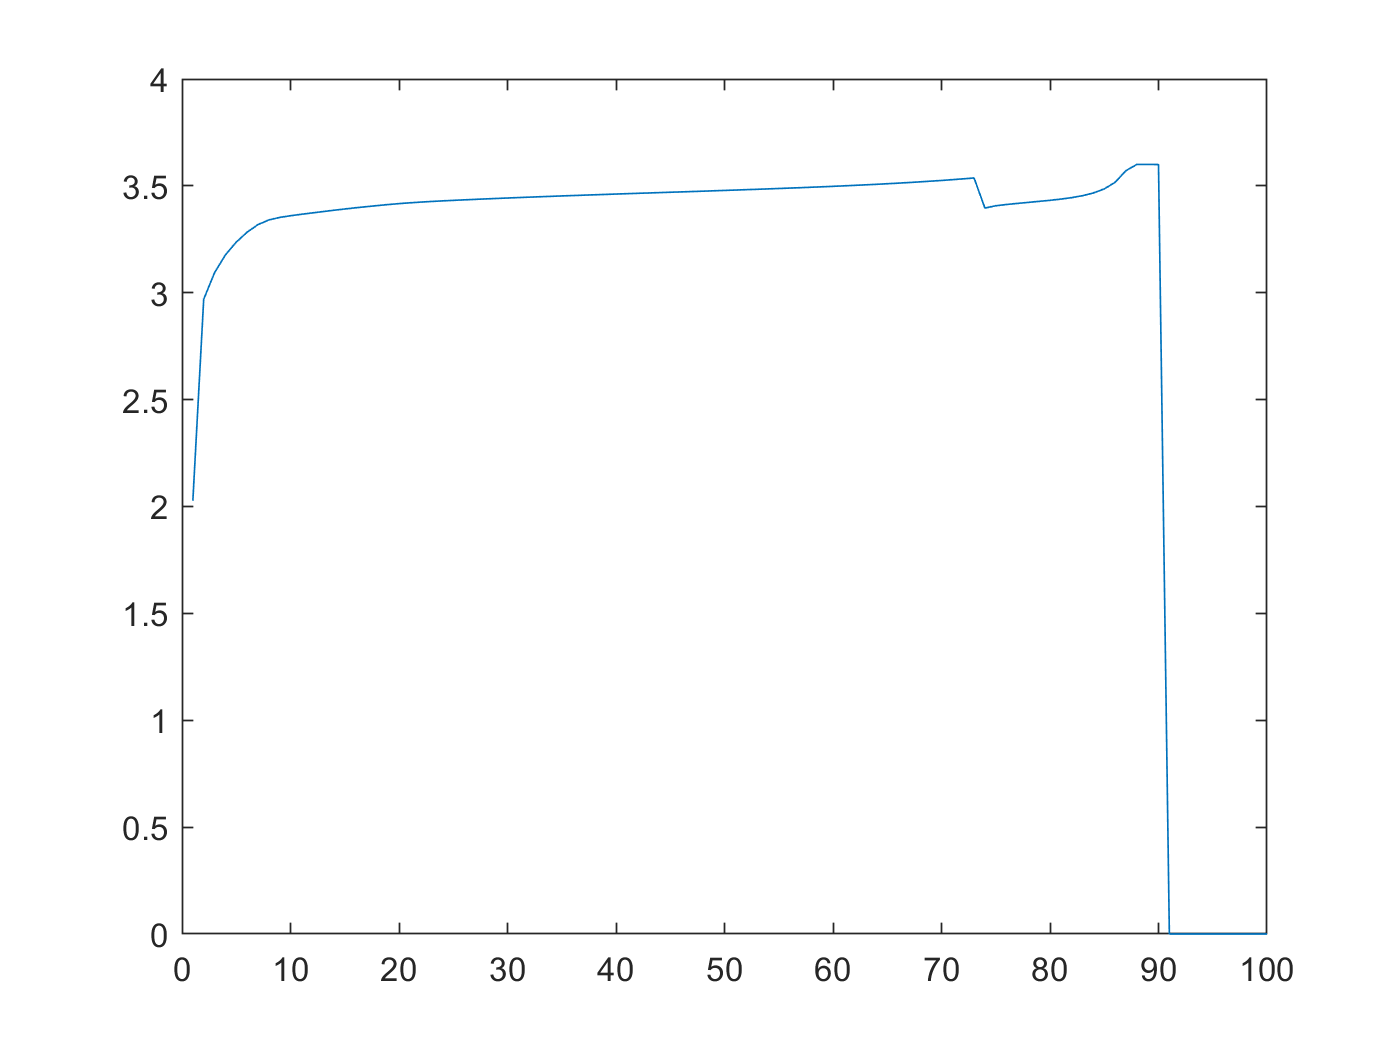

% https://kr.mathworks.com/matlabcentral/answers/6038-convert-zeros-to-nan
% https://kr.mathworks.com/matlabcentral/answers/85568-how-to-convert-nan-to-zero?s_tid=ta_ans_results

new_y_c_fix_fill_zero = new_y_c;
%% not work
%new_y_c_fix_fill_zero(new_y_c_fix_fill_zero==NaN)=0;
%new_y_c_fix_fill_zeroA(find(new_y_c_fix_fill_zero==NaN)) = 0;

%% work
new_y_c_fix_fill_zero(isnan(new_y_c_fix_fill_zero)) = 0;
plot(new_y_c_fix_fill_zero)

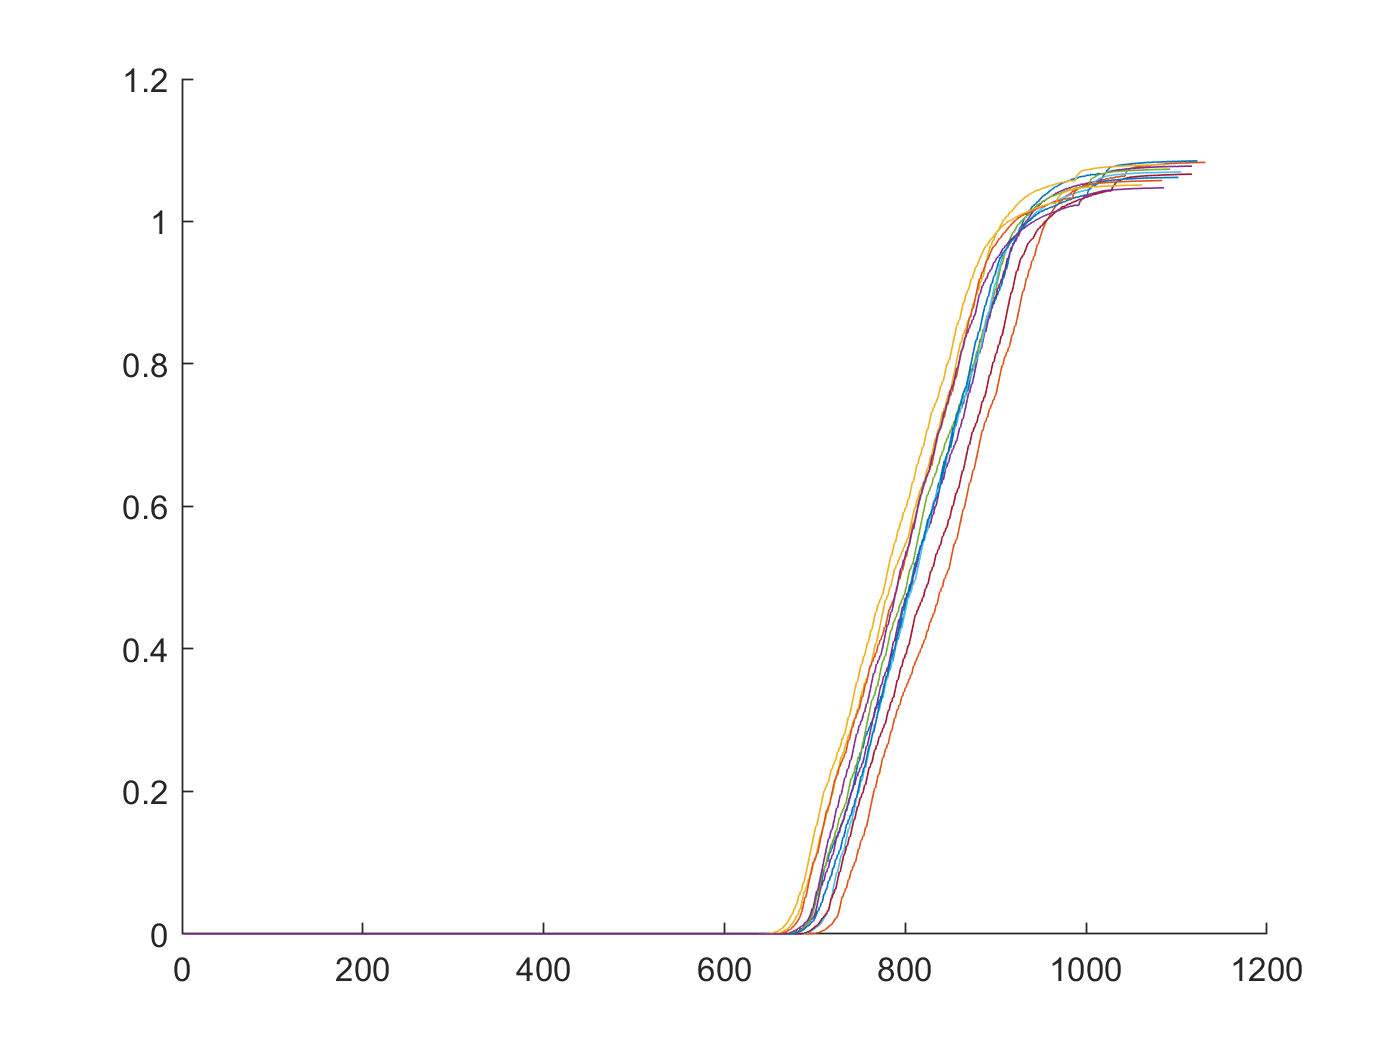

figure
hold on
for i=1:trainData(3).cycle_life-3
    if rem(i,100) == 0
        plot(trainData(3).cycles(i).Qd)
    end
end 
hold off 

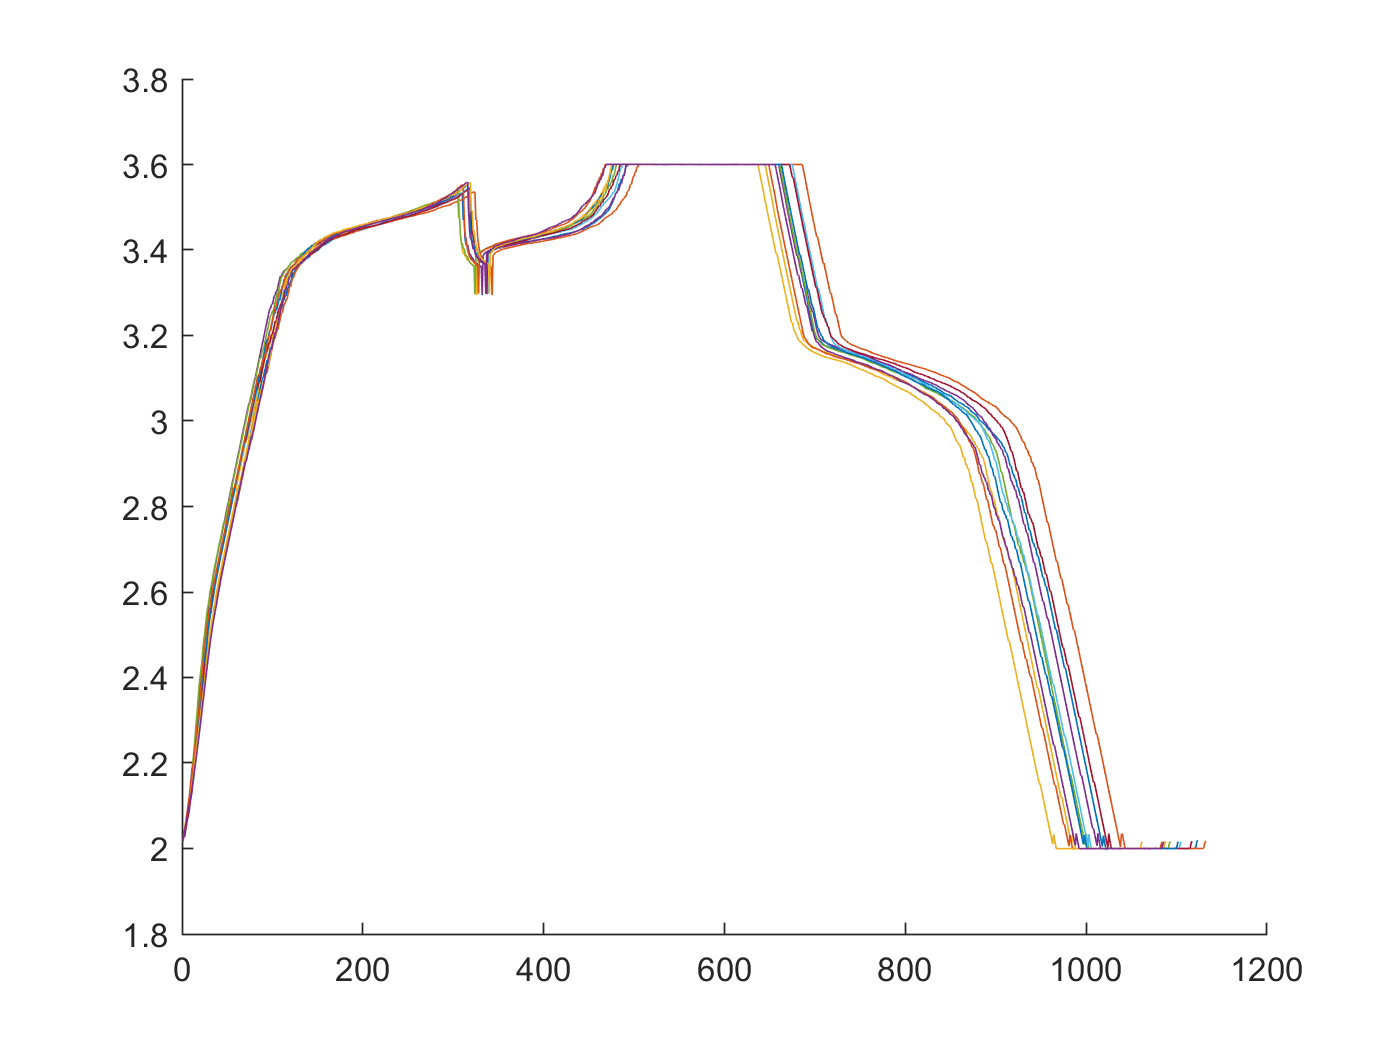

figure
hold on
for i=1:trainData(3).cycle_life-3
    if rem(i,100) == 0
    plot(trainData(3).cycles(i).V')
    end
end 
hold off 

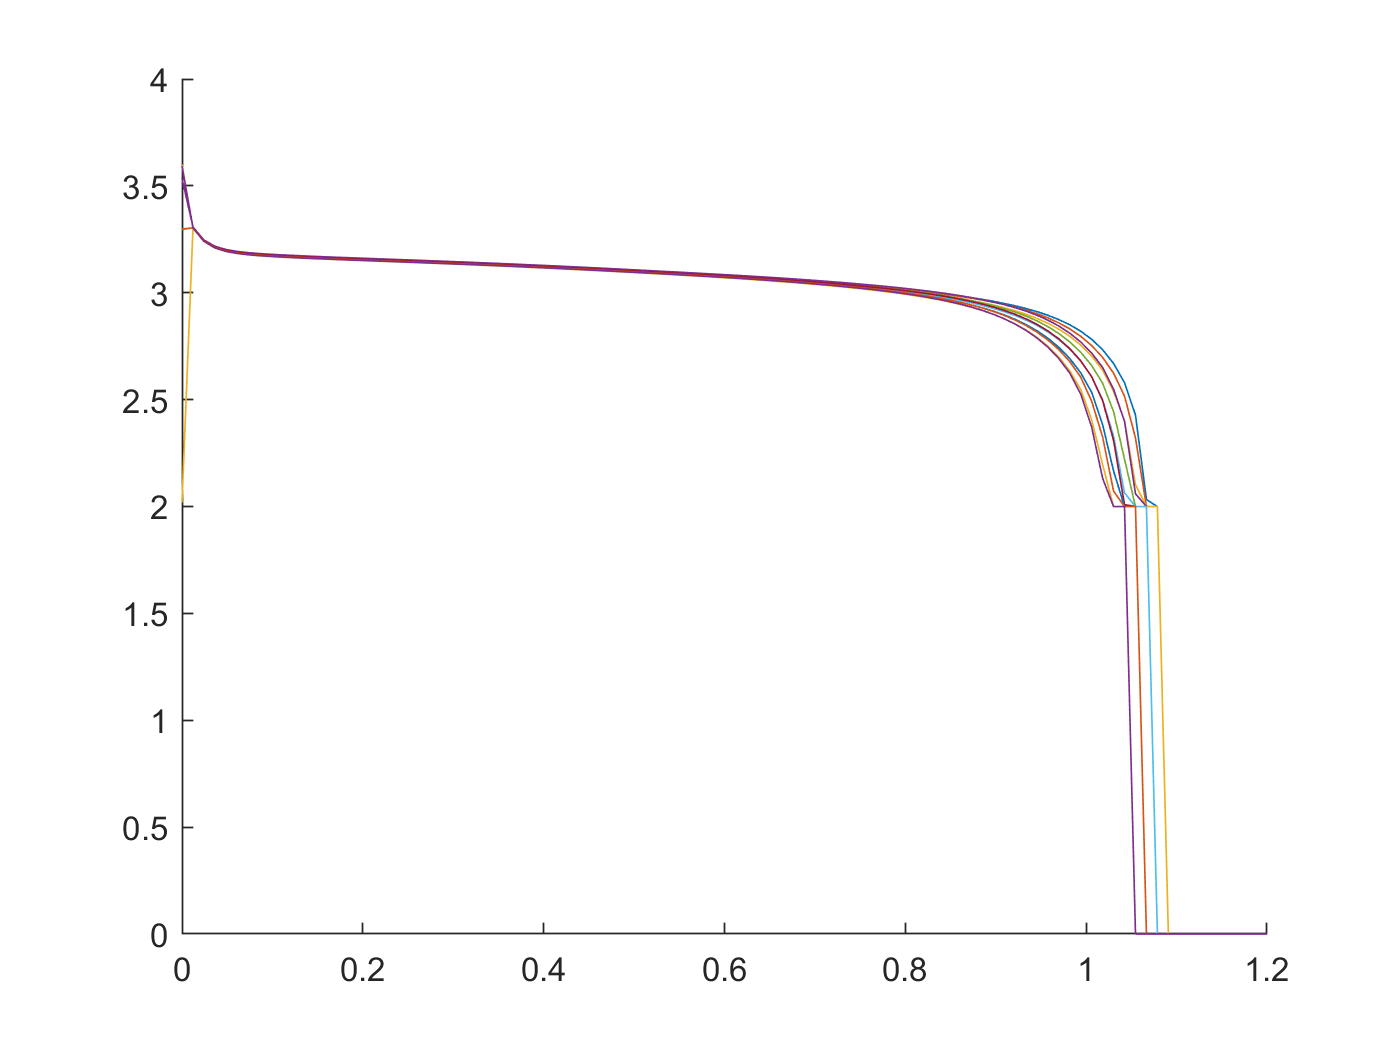


figure
hold on

for i=3:trainData(3).cycle_life-3
    if rem(i,100) == 0
    %[x_d, index] = unique(trainData(3).cycles(cycleNum).Qd);
    [x_d, index] = unique(trainData(3).cycles(i).Qd,"last");
    
    y_d = trainData(3).cycles(i).V(index);
    new_x_d = linspace(0,1.2,100);
    new_y_d = interp1(x_d,y_d,new_x_d,'linear'); 
    new_y_d(isnan(new_y_d)) = 0;
    plot(new_x_d,new_y_d);
    end
end 
hold off

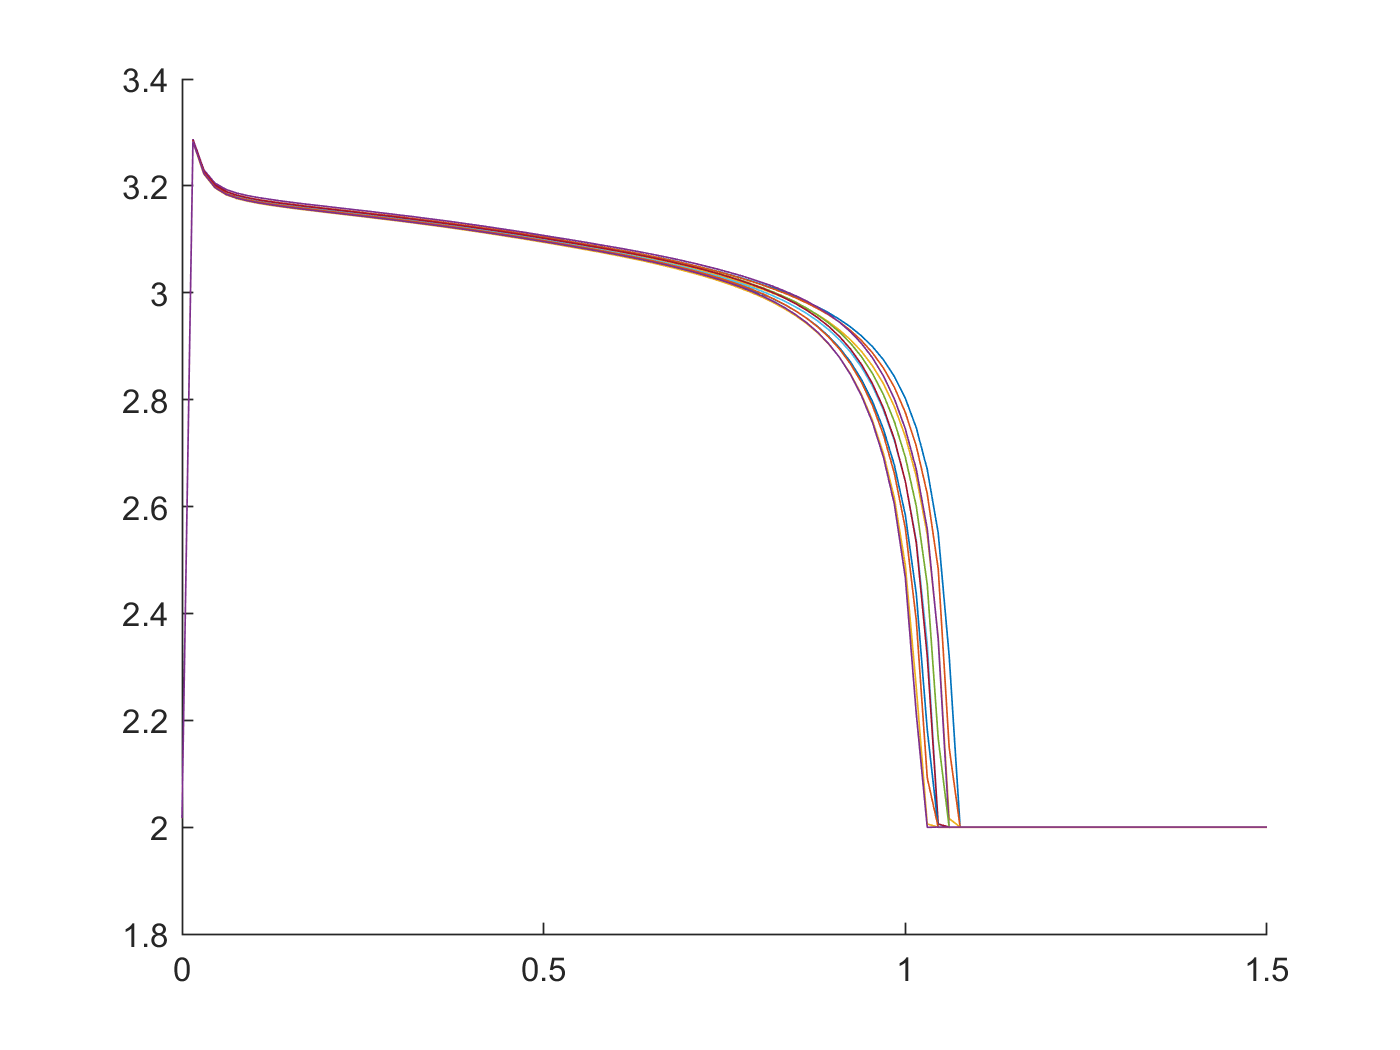

figure
hold on

for i=3:trainData(3).cycle_life-3
    if rem(i,100) == 0
    Qd_tmp = trainData(3).cycles(i).Qd;
    Qd_tmp(Qd_tmp<0) = 0;
    %[x_d, index] = unique(trainData(3).cycles(cycleNum).Qd);
    [xq, index] = unique(Qd_tmp,"first");
    
    yV = trainData(3).cycles(i).V(index);
    xq_new = linspace(0,1.5,100);
    yV = interp1(xq,yV,xq_new,'linear'); 
    yV = fillmissing(yV,'nearest');
    %new_y_d(isnan(new_y_d)) = 0;
    plot(xq_new,yV);
    end
end 
hold off

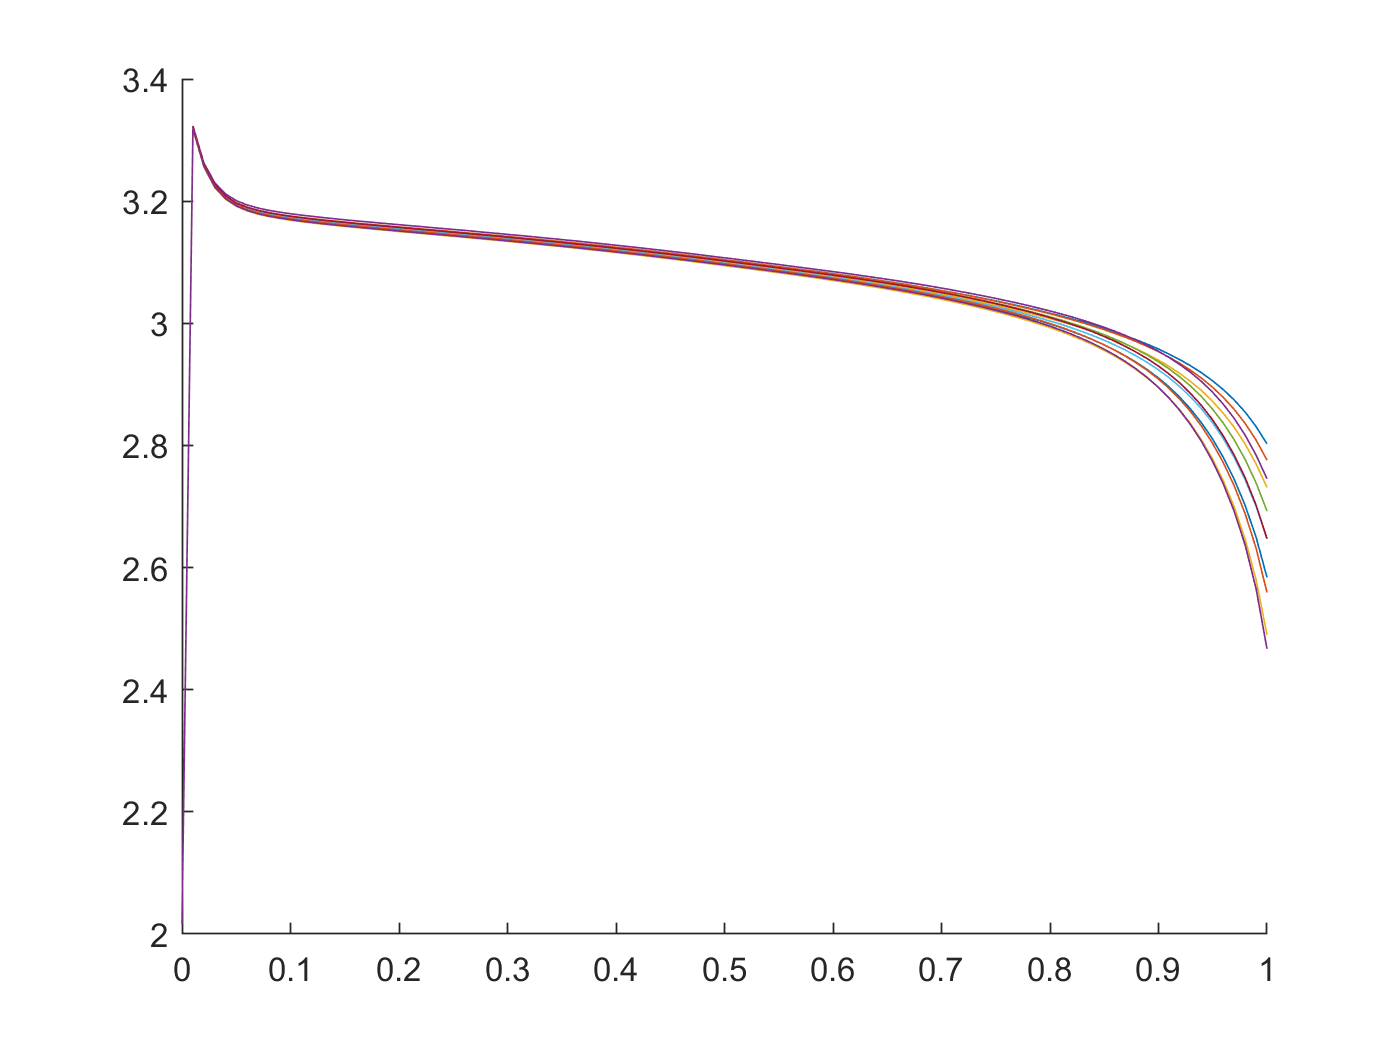

figure
hold on

for i=3:trainData(3).cycle_life-3
    if rem(i,100) == 0
    Qd_tmp = trainData(3).cycles(i).Qd;
    Qd_tmp(Qd_tmp<0) = 0;
    %[x_d, index] = unique(trainData(3).cycles(cycleNum).Qd);
    [xq, index] = unique(Qd_tmp,"first");
    
    yV = trainData(3).cycles(i).V(index);
    xq_new = linspace(0,1.0,100);
    yV = interp1(xq,yV,xq_new,'linear'); 
    yV = fillmissing(yV,'nearest');
    %new_y_d(isnan(new_y_d)) = 0;
    plot(xq_new,yV);
    end
end 
hold off

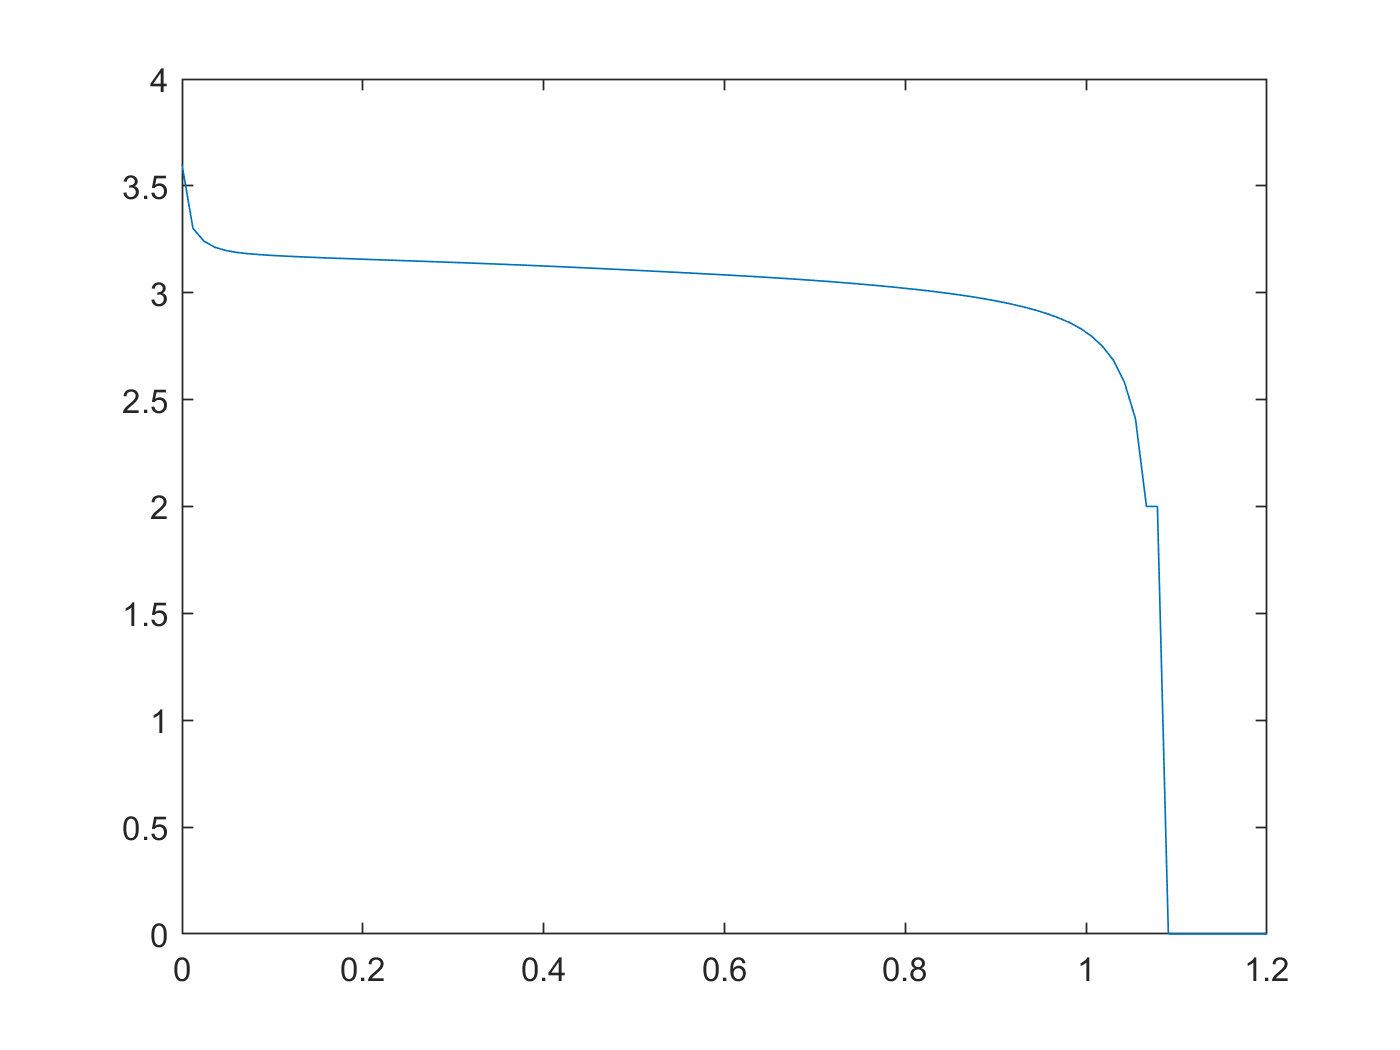


%[x_d, index] = unique(trainData(3).cycles(cycleNum).Qd);
[x_d, index] = unique(trainData(3).cycles(cycleNum).Qd,"last");

y_d = trainData(3).cycles(cycleNum).V(index);
new_x_d = linspace(0,1.2,100);
new_y_d = interp1(x_d,y_d,new_x_d,'linear'); 
new_y_d(isnan(new_y_d)) = 0;
plot(new_x_d,new_y_d);

%{
x_indexs = find(trainData(3).cycles(2).Qd')
x_index = x_indexs(1)
x = trainData(3).cycles(2).Qd';
x = x(x_index : end)
y = trainData(3).cycles(2).V';
y = y(x_index : end)
new_x = linspace(0,1.2,100);
new_y = interp1(x,y,new_x,'linear'); 
plot(new_y)
%}   